kappa_ext = 1.2323e6;
kappa_tot = kappa_ext + .22653e6; %kappa_int = 0.2265MHz. These values correspond to ng = 0 and phi = 0 for Jules' sample in March 2021 small fridge
% kerr = 0;
kerr = -.5e6;
detunings = linspace(-5*kappa_tot, 5*kappa_tot, 1000);
detunings_spacing_1 = mean(abs(diff(detunings)));
number_detunings_2 = 300;
omega_0 = 5.7851e9; % in Hz. 
h = 6.626e-34; % just h, not hbar since omega_0 is in Hz
plot_figures = 1;
power_specific_in_dBm = - 150; % in dBm at sample capacitor
specific_detuning = 1e6;

fridge_attenuation = 81;
critical_detuning = (kerr/abs(kerr))*sqrt(3) * kappa_tot/2; % the detuning below (above, depending on sign of Kerr)which you 
% will not see any bifurcation
power_critical_in_watts = 3^.5/9*kappa_tot^3/abs(kerr)/kappa_ext*h*(omega_0 + critical_detuning); % input power required for onset of 
% bifurcation at the critical detuning.
power_critical_in_dBm = 10*log10(power_critical_in_watts/1e-3);
power_specific_in_watts = 1e-3*10^(power_specific_in_dBm/10);
power_input_start_dBm = -65 - fridge_attenuation; 
power_input_stop_dBm = -55 - fridge_attenuation; % 81dB is approx fridge attenuation. 
power_input_start_watts = 1e-3.*10.^(power_input_start_dBm/10);
power_input_stop_watts = 1e-3.*10.^(power_input_stop_dBm/10);

% power_input_in_watts = linspace(power_input_start_watts, power_input_stop_watts, 5);
% power_input_in_dBm = 10*log10(power_input_in_watts/1e-3);

power_input_in_dBm = linspace(power_input_start_dBm, power_input_stop_dBm, 100);
power_input_in_watts = 1e-3.*10.^(power_input_in_dBm/10);

power_critical_in_numbers = power_critical_in_watts/h/(omega_0 + critical_detuning);
power_specific_in_numbers = power_specific_in_watts/h/(omega_0 + specific_detuning);
power_input_in_numbers = power_input_in_watts/h/omega_0;
kerr = kerr/1e6;
kappa_ext = kappa_ext /1e6;
kappa_tot = kappa_tot/ 1e6;
detunings = detunings/ 1e6;
critical_detuning = critical_detuning/1e6;
specific_detuning = specific_detuning/1e6;
power_input_in_numbers = power_input_in_numbers/1e6;
power_critical_in_numbers = power_critical_in_numbers/1e6;
power_specific_in_numbers = power_specific_in_numbers/1e6;
[detunings_array, power_input_array] = meshgrid(detunings, power_input_in_numbers);
amp_roots = zeros([size(detunings_array),3]);
amp_roots_critical_power = zeros([size(detunings), 3]);
amp_roots_critical_detuning = squeeze(zeros([size(power_input_in_numbers), 3]));
amp_roots_specific_power = zeros([size(detunings), 3]);
amp_roots_specific_detuning = squeeze(zeros([size(power_input_in_numbers), 3]));
detunings = detunings *1e6;
kappa_tot = kappa_tot*1e6;
kerr = kerr*1e6;
kappa_ext = kappa_ext*1e6;
specific_detuning = specific_detuning *1e6;
critical_detuning = critical_detuning *1e6;
bifurcation_power_1_watts = 2/27.*detunings.^3./kerr.*((1+9*kappa_tot^2/4./detunings.^2)+(1-3*kappa_tot^2/4./detunings.^2).^1.5)*h.*(omega_0 + detunings)./kappa_ext;
bifurcation_power_1_watts_specific_detuning = 2/27.*specific_detuning.^3./kerr.*((1+9*kappa_tot^2/4./specific_detuning.^2)+(1-3*kappa_tot^2/4./specific_detuning.^2).^1.5)*h.*(omega_0 + specific_detuning)./kappa_ext;
bifurcation_power_1_watts_critical_detuning = 2/27.*critical_detuning.^3./kerr.*((1+9*kappa_tot^2/4./critical_detuning.^2)+(1-3*kappa_tot^2/4./critical_detuning.^2).^1.5)*h.*(omega_0 + critical_detuning)./kappa_ext;
bifurcation_power_2_watts = 2/27.*detunings.^3/kerr.*((1+9*kappa_tot^2/4./detunings.^2)-(1-3*kappa_tot^2/4./detunings.^2).^1.5)*h.*(omega_0 + detunings)./kappa_ext;
bifurcation_power_2_watts_specific_detuning = 2/27.*specific_detuning.^3./kerr.*((1+9*kappa_tot^2/4./specific_detuning.^2)-(1-3*kappa_tot^2/4./specific_detuning.^2).^1.5)*h.*(omega_0 + specific_detuning)./kappa_ext;
bifurcation_power_2_watts_critical_detuning = 2/27.*critical_detuning.^3./kerr.*((1+9*kappa_tot^2/4./critical_detuning.^2)-(1-3*kappa_tot^2/4./critical_detuning.^2).^1.5)*h.*(omega_0 + critical_detuning)./kappa_ext;

bifurcation_power_1_dBm = 10.*log10(bifurcation_power_1_watts./1e-3);
bifurcation_power_2_dBm = 10.*log10(bifurcation_power_2_watts./1e-3);
bifurcation_power_1_dBm_critical_detuning = 10.*log10(bifurcation_power_1_watts_critical_detuning./1e-3);
bifurcation_power_2_dBm_critical_detuning = 10.*log10(bifurcation_power_2_watts_critical_detuning./1e-3);
bifurcation_power_1_dBm_specific_detuning = 10.*log10(bifurcation_power_1_watts_specific_detuning./1e-3);
bifurcation_power_2_dBm_specific_detuning = 10.*log10(bifurcation_power_2_watts_specific_detuning./1e-3);

detunings = detunings/1e6;
specific_detuning = specific_detuning /1e6;
critical_detuning = critical_detuning /1e6;
kappa_tot = kappa_tot/1e6;
kappa_ext = kappa_ext/1e6;
kerr = kerr/1e6;
bifurcation_power_1_dBm(imag(bifurcation_power_1_watts) ~=0) = nan;
bifurcation_power_2_dBm(imag(bifurcation_power_2_watts) ~=0) = nan;
bifurcation_power_1_dBm_critical_detuning(imag(bifurcation_power_1_watts_critical_detuning) ~=0) = nan;
bifurcation_power_2_dBm_critical_detuning(imag(bifurcation_power_2_watts_critical_detuning) ~=0) = nan;
bifurcation_power_1_dBm_specific_detuning(imag(bifurcation_power_1_watts_specific_detuning) ~=0) = nan;
bifurcation_power_2_dBm_specific_detuning(imag(bifurcation_power_2_watts_specific_detuning) ~=0) = nan;

for i = 1: size(detunings_array,1)
    amp_roots_critical_detuning(i,:) = roots([kerr^2, -2*kerr.*critical_detuning, (critical_detuning.^2 + kappa_tot^2 / 4),...
            -kappa_ext .* power_input_in_numbers(i)]);
    amp_roots_specific_detuning(i,:) = roots([kerr^2, -2*kerr.*specific_detuning, (specific_detuning.^2 + kappa_tot^2 / 4),...
        -kappa_ext .* power_input_in_numbers(i)]);
    for j = 1: size(detunings_array,2)
        amp_roots(i,j,:) = roots([kerr^2, -2*kerr.*detunings_array(i,j), (detunings_array(i,j).^2 + kappa_tot^2 / 4),...
            -kappa_ext * power_input_array(i,j)]);
        amp_roots_critical_power(1,j,:) = roots([kerr^2, -2*kerr.*detunings(j), (detunings(j).^2 + kappa_tot^2 / 4),...
            -kappa_ext * power_critical_in_numbers]);
        amp_roots_specific_power(1,j,:) = roots([kerr^2, -2*kerr.*detunings(j), (detunings(j).^2 + kappa_tot^2 / 4),...
            -kappa_ext * power_specific_in_numbers]);
    end
end

amp_roots(imag(amp_roots) ~=0) = 0;
amp_roots_critical_power(imag(amp_roots_critical_power) ~=0) = 0;
amp_roots_critical_detuning(imag(amp_roots_critical_detuning) ~=0) = 0;
amp_roots_specific_power(imag(amp_roots_specific_power) ~=0) = 0;
amp_roots_specific_detuning(imag(amp_roots_specific_detuning) ~=0) = 0;

amp_roots_critical_power = squeeze(amp_roots_critical_power);
amp_roots_critical_detuning = squeeze(amp_roots_critical_detuning);
amp_roots_specific_power = squeeze(amp_roots_specific_power);
amp_roots_specific_detuning = squeeze(amp_roots_specific_detuning);
main_s11 = zeros([size(detunings_array)]);
first_zero_root_1 = zeros(size(detunings_array,1),1);
first_zero_root_3 = zeros(size(detunings_array,1),1);

detunings_array_reps = repmat(detunings_array, [1, 1, 3]);
detunings_array_reps_critical_power = repmat(detunings,[3,1])';

s11 = ((detunings_array_reps - kerr .* amp_roots) - 1i*(kappa_tot -...
2*kappa_ext)/2)./((detunings_array_reps - kerr .* amp_roots) -1i*kappa_tot/2);

s11_critical_power = ((detunings_array_reps_critical_power - kerr .* amp_roots_critical_power) - 1i*(kappa_tot -...
2*kappa_ext)/2)./((detunings_array_reps_critical_power - kerr .* amp_roots_critical_power) -1i*kappa_tot/2);

s11_critical_detuning = ((critical_detuning - kerr .* amp_roots_critical_detuning) - 1i*(kappa_tot -...
2*kappa_ext)/2)./((critical_detuning - kerr .* amp_roots_critical_detuning) -1i*kappa_tot/2);

s11_specific_power = ((detunings_array_reps_critical_power - kerr .* amp_roots_specific_power) - 1i*(kappa_tot -...
2*kappa_ext)/2)./((detunings_array_reps_critical_power - kerr .* amp_roots_specific_power) -1i*kappa_tot/2);

s11_specific_detuning = ((specific_detuning - kerr .* amp_roots_specific_detuning) - 1i*(kappa_tot -...
2*kappa_ext)/2)./((specific_detuning - kerr .* amp_roots_specific_detuning) -1i*kappa_tot/2);

s11(amp_roots == 0) = 0;
s11_critical_power(amp_roots_critical_power == 0) = 0;
s11_critical_detuning (amp_roots_critical_detuning == 0) = 0;
s11_specific_power(amp_roots_specific_power == 0) = 0;
s11_specific_detuning (amp_roots_specific_detuning == 0) = 0;


for i = 1: size(detunings_array,1)
    first_zero_root_3(i) = find(amp_roots(i,:,3) == 0, 1) - 1;
    first_zero_root_1(i) = length(amp_roots(i,:,1)) - find(flip(amp_roots(i,:,1) ~= 0),1) + 1;
    main_s11(i,:) = [s11(i,1:first_zero_root_3(i),3), s11(i,first_zero_root_3(i) + 1: first_zero_root_1(i), 1), s11(i,first_zero_root_1(i) + 1: end, 3)];
end

main_s11_forward = zeros([size(detunings_array)]);
main_s11_reverse = zeros([size(detunings_array)]);
main_s11_forward_power = zeros([size(detunings_array)]);
main_s11_reverse_power = zeros([size(detunings_array)]);
first_zero_root_1 = zeros(size(detunings_array,1),1);
first_zero_root_3 = zeros(size(detunings_array,1),1);
for i = 1: size(detunings_array,1)
    number_zeros_1 = sum(double(amp_roots(i,:,1) == 0));
    number_zeros_3 = sum(double(amp_roots(i,:,3) == 0));
    if number_zeros_1 > 0 && number_zeros_3 > 0
        first_zero_root_3(i) = find(amp_roots(i,:,3) == 0, 1) - 1;
        first_zero_root_1(i) = length(amp_roots(i,:,1)) - find(flip(amp_roots(i,:,1) ~= 0),1) + 1;
        main_s11_reverse_temp = s11(i,:,1);
        s11_3_temp = s11(i,:,3);
        zero_entries = (main_s11_reverse_temp == 0);
        main_s11_reverse_temp(zero_entries) = s11_3_temp(zero_entries);
        main_s11_forward(i,:) = [s11(i,1:first_zero_root_3(i),3), s11(i,first_zero_root_3(i) + 1: first_zero_root_1(i), 1), s11(i,first_zero_root_1(i) + 1: end, 3)]; 
        main_s11_reverse(i,:) = main_s11_reverse_temp;
    else 
        main_s11_forward = s11(:,:,3);
        main_s11_reverse = s11(:,:,3);
    end
end
for i = 1: size(power_input_array,2)
    number_zeros_1 = sum(double(amp_roots(:,i,1) == 0));
    number_zeros_3 = sum(double(amp_roots(:,i,3) == 0));
    if number_zeros_1 > 0 && number_zeros_3 > 0
        first_zero_root_3(i) = find(amp_roots(:,i,3) == 0, 1) - 1;
        first_zero_root_1(i) = length(amp_roots(:,i,1)) - find(flip(amp_roots(:,i,1) ~= 0),1) + 1;
        main_s11_reverse_temp_power = s11(:,i,1);
        s11_3_temp = s11(:,i,3);
        zero_entries = (main_s11_reverse_temp_power == 0);
        main_s11_reverse_temp_power(zero_entries) = s11_3_temp(zero_entries);
        main_s11_forward_power(:,i) = [s11(1:first_zero_root_3(i),i,3); s11(first_zero_root_3(i) + 1: end,i, 1)];         
%         main_s11_forward_power(:,i) = [s11(1:first_zero_root_3(i),i,3); s11(first_zero_root_3(i) + 1: first_zero_root_1(i),i, 1); s11(first_zero_root_1(i) + 1: end,i, 3)]; 
        main_s11_reverse_power(:,i) = main_s11_reverse_temp_power;
%     else 
%         main_s11_forward_power = s11(:,:,3);
%         main_s11_reverse_power = s11(:,:,3);
    end
end

main_s11_forward_critical_power = zeros([size(detunings)])';
main_s11_reverse_critical_power = zeros([size(detunings)])';
main_s11_forward_specific_power = zeros([size(detunings)])';
main_s11_reverse_specific_power = zeros([size(detunings)])';
first_zero_root_1 = zeros(size(detunings_array,1),1);
first_zero_root_3 = zeros(size(detunings_array,1),1);
number_zeros_1 = sum(double(amp_roots_critical_power(:,1) == 0));
number_zeros_3 = sum(double(amp_roots_critical_power(:,3) == 0));
if number_zeros_1 > 0 && number_zeros_3 > 0
    first_zero_root_3 = find(amp_roots_critical_power(:,3) == 0, 1) - 1;
    first_zero_root_1 = length(amp_roots_critical_power(:,1)) - find(flip(amp_roots_critical_power(:,1) ~= 0),1) + 1;
    main_s11_critical_power_reverse_temp = s11_critical_power(:,1);
    s11_critical_power_3_temp = s11_critical_power(:,3);
    zero_entries = (main_s11_critical_power_reverse_temp == 0);
    main_s11_critical_power_reverse_temp(zero_entries) = s11_critical_power_3_temp(zero_entries);
    main_s11_forward_critical_power = [s11_critical_power(1:first_zero_root_3,3); s11_critical_power(first_zero_root_3 + 1: first_zero_root_1, 1); s11_critical_power(first_zero_root_1 + 1: end, 3)]; 
    main_s11_reverse_critical_power = main_s11_critical_power_reverse_temp;
else 
    main_s11_forward_critical_power = s11_critical_power(:,3);
    main_s11_reverse_critical_power = s11_critical_power(:,3);
end

first_zero_root_1 = zeros(size(detunings_array,1),1);
first_zero_root_3 = zeros(size(detunings_array,1),1);
number_zeros_1 = sum(double(amp_roots_specific_power(:,1) == 0));
number_zeros_3 = sum(double(amp_roots_specific_power(:,3) == 0));
if number_zeros_1 > 0 && number_zeros_3 > 0
    first_zero_root_3 = find(amp_roots_specific_power(:,3) == 0, 1) - 1;
    first_zero_root_1 = length(amp_roots_specific_power(:,1)) - find(flip(amp_roots_specific_power(:,1) ~= 0),1) + 1;
    main_s11_specific_power_reverse_temp = s11_specific_power(:,1);
    s11_specific_power_3_temp = s11_specific_power(:,3);
    zero_entries = (main_s11_critical_power_reverse_temp == 0);
    main_s11_specific_power_reverse_temp(zero_entries) = s11_specific_power_3_temp(zero_entries);
    main_s11_forward_specific_power = [s11_specific_power(1:first_zero_root_3,3); s11_specific_power(first_zero_root_3 + 1: first_zero_root_1, 1); s11_specific_power(first_zero_root_1 + 1: end, 3)]; 
    main_s11_reverse_specific_power = main_s11_specific_power_reverse_temp;
else 
    main_s11_forward_specific_power = s11_specific_power(:,3);
    main_s11_reverse_specific_power = s11_specific_power(:,3);
end

main_s11_forward_critical_detuning = zeros([size(power_input_in_numbers)])';
main_s11_reverse_critical_detuning = zeros([size(power_input_in_numbers)])';
main_s11_forward_specific_detuning = zeros([size(power_input_in_numbers)])';
main_s11_reverse_specific_detuning = zeros([size(power_input_in_numbers)])';
first_zero_root_1 = zeros(size(power_input_in_numbers,1),1);
first_zero_root_3 = zeros(size(power_input_in_numbers,1),1);
number_zeros_1 = sum(double(amp_roots_critical_detuning(:,1) == 0));
number_zeros_3 = sum(double(amp_roots_critical_detuning(:,3) == 0));
if number_zeros_1 > 0 && number_zeros_3 > 0
    first_zero_root_3 = find(amp_roots_critical_detuning(:,3) == 0, 1) - 1;
    first_zero_root_1 = length(amp_roots_critical_detuning(:,1)) - find(flip(amp_roots_critical_detuning(:,1) ~= 0),1) + 1;
    main_s11_reverse_critical_detuning_temp_power = s11_critical_detuning(:,1);
    s11_3_critical_detuning_temp = s11_critical_detuning(:,3);
    zero_entries = (main_s11_reverse_critical_detuning_temp_power == 0);
    main_s11_reverse_critical_detuning_temp_power(zero_entries) = s11_3_critical_detuning_temp(zero_entries);
%     main_s11_forward_critical_detuning = [s11_critical_detuning(1:first_zero_root_3,3); s11_critical_detuning(first_zero_root_3 + 1: end, 1)];         
    main_s11_forward_critical_detuning = [s11_critical_detuning(1:first_zero_root_3,3); s11_critical_detuning(first_zero_root_3 + 1: first_zero_root_1, 1); s11_critical_detuning(first_zero_root_1 + 1: end, 3)]; 
    main_s11_reverse_critical_detuning = main_s11_reverse_critical_detuning_temp_power;
else 
    main_s11_forward_critical_detuning = s11_critical_detuning(:,3);
    main_s11_reverse_critical_detuning = s11_critical_detuning(:,3);
end

first_zero_root_1 = zeros(size(power_input_in_numbers,1),1);
first_zero_root_3 = zeros(size(power_input_in_numbers,1),1);
number_zeros_1 = sum(double(amp_roots_specific_detuning(:,1) == 0));
number_zeros_3 = sum(double(amp_roots_specific_detuning(:,3) == 0));
if number_zeros_1 > 0 && number_zeros_3 > 0
    first_zero_root_3 = find(amp_roots(:,3) == 0, 1) - 1;
    first_zero_root_1 = length(amp_roots(:,1)) - find(flip(amp_roots_specific_detuning(:,1) ~= 0),1) + 1;
    main_s11_reverse_specific_detuning_temp_power = s11(:,1);
    s11_3_specific_detuning_temp = s11(:,3);
    zero_entries = (main_s11_reverse_specific_detuning_temp_power == 0);
    main_s11_reverse_specific_detuning_temp_power(zero_entries) = s11_3_specific_detuning_temp(zero_entries);
%     main_s11_forward_specific_detuning = [s11_specific_detuning(1:first_zero_root_3,3); s11_specific_detuning(first_zero_root_3 + 1: end, 1)];         
    main_s11_forward_specific_detuning = [s11_specific_detuning(1:first_zero_root_3,3); s11_specific_detuning(first_zero_root_3 + 1: first_zero_root_1, 1); s11_specific_detuning(first_zero_root_1 + 1: end, 3)]; 
    main_s11_reverse_specific_detuning = main_s11_reverse_specific_detuning_temp_power;
else 
    disp('yes')
    main_s11_forward_specific_detuning = s11_specific_detuning(:,3);
    main_s11_reverse_specific_detuning = s11_specific_detuning(:,3);
end

yes


check_detuning_number = 394

check_power_input = 3

check_power_input = 70

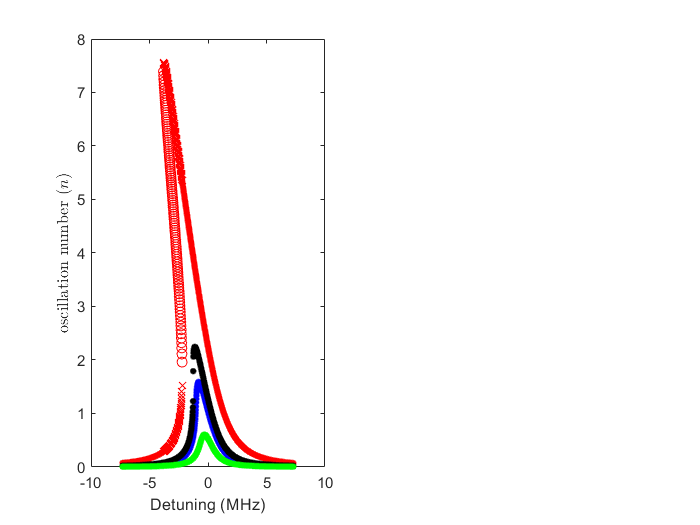

if plot_figures == 1
    check_detuning_number = 394
    check_power_input = 3
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    plotting_y_1 = squeeze(amp_roots(check_power_input,:,1));
    plotting_y_2 = squeeze(amp_roots(check_power_input,:,2));
    plotting_y_3 = squeeze(amp_roots(check_power_input,:,3));
    
    
    monostable_root = plotting_y_1 + plotting_y_3;
    monostable_root(plotting_y_1.*plotting_y_3 ~= 0) = 0;
    bistable_root_1 = plotting_y_1;
    bistable_root_2 = plotting_y_3;
    bistable_root_1(plotting_y_1.*plotting_y_3 == 0) = 0;
    bistable_root_2(plotting_y_1.*plotting_y_3 == 0) = 0;
    plotting_x_monostable = detunings_array(check_power_input,:);
    plotting_x_bistable_1 = detunings_array(check_power_input,:);
    plotting_x_bistable_2 = detunings_array(check_power_input,:);
    plotting_x_monostable(monostable_root == 0) = [];
    monostable_root(monostable_root == 0) = [];
    plotting_x_bistable_1 (bistable_root_1 == 0) = [];
    bistable_root_1(bistable_root_1 == 0) = [];
    plotting_x_bistable_2(bistable_root_2 == 0) = [];
    bistable_root_2(bistable_root_2 == 0) = [];
    
    plotting_x_1 = detunings_array(check_power_input,:);
    plotting_x_2 = plotting_x_1;
    plotting_x_3 = plotting_x_1;
    
    plotting_x_1(plotting_y_1 == 0) = [];
    plotting_y_1(plotting_y_1 == 0) = [];
    plotting_x_2(plotting_y_2 == 0) = [];
    plotting_y_2(plotting_y_2 == 0) = [];
    plotting_x_3(plotting_y_3 == 0) = [];
    plotting_y_3(plotting_y_3 == 0) = [];
    figure
    subplot(1,2,1)
    % this plots solution 1, 2 and 3 without distinguishing between mono,
    % bi and unstable.
%     plot(plotting_x_1, plotting_y_1,'x')
%     hold on
%     plot(plotting_x_2, plotting_y_2,'o')
%     plot(plotting_x_3, plotting_y_3,'.')
    
    plot(plotting_x_monostable, monostable_root,'b.', 'markerSize', 12)
    hold on
    plot(plotting_x_bistable_1, bistable_root_1,'bx')
    plot(plotting_x_bistable_2, bistable_root_2,'bx')
    plot(plotting_x_2, plotting_y_2,'bo')
    
    check_power_input = 70
    plotting_y_1 = squeeze(amp_roots(check_power_input,:,1));
    plotting_y_2 = squeeze(amp_roots(check_power_input,:,2));
    plotting_y_3 = squeeze(amp_roots(check_power_input,:,3));
    plotting_x_1 = detunings_array(check_power_input,:);
    plotting_x_2 = plotting_x_1;
    plotting_x_3 = plotting_x_1;
    
    monostable_root = plotting_y_1 + plotting_y_3;
    monostable_root(plotting_y_1.*plotting_y_3 ~= 0) = 0;
    bistable_root_1 = plotting_y_1;
    bistable_root_2 = plotting_y_3;
    bistable_root_1(plotting_y_1.*plotting_y_3 == 0) = 0;
    bistable_root_2(plotting_y_1.*plotting_y_3 == 0) = 0;
    plotting_x_monostable = detunings_array(check_power_input,:);
    plotting_x_bistable_1 = detunings_array(check_power_input,:);
    plotting_x_bistable_2 = detunings_array(check_power_input,:);
    plotting_x_monostable(monostable_root == 0) = [];
    monostable_root(monostable_root == 0) = [];
    plotting_x_bistable_1 (bistable_root_1 == 0) = [];
    bistable_root_1(bistable_root_1 == 0) = [];
    plotting_x_bistable_2(bistable_root_2 == 0) = [];
    bistable_root_2(bistable_root_2 == 0) = [];
    
    plotting_x_1(plotting_y_1 == 0) = [];
    plotting_y_1(plotting_y_1 == 0) = [];
    plotting_x_2(plotting_y_2 == 0) = [];
    plotting_y_2(plotting_y_2 == 0) = [];
    plotting_x_3(plotting_y_3 == 0) = [];
    plotting_y_3(plotting_y_3 == 0) = [];
    
    
    plot(plotting_x_monostable, monostable_root,'r.', 'markerSize', 12)
    plot(plotting_x_bistable_1, bistable_root_1,'rx')
    plot(plotting_x_bistable_2, bistable_root_2,'rx')
    plot(plotting_x_2, plotting_y_2,'ro')
    
%     plot(plotting_x_1, plotting_y_1,'x')
%     plot(plotting_x_2, plotting_y_2,'o')
%     plot(plotting_x_3, plotting_y_3,'.')

%     title(['All roots oscillation number for input power ' num2str(power_input_in_dBm(check_power_input) +  fridge_attenuation) 'dBm'])
    
    plotting_y_1 = squeeze(amp_roots_critical_power(:,1));
    plotting_y_2 = squeeze(amp_roots_critical_power(:,2));
    plotting_y_3 = squeeze(amp_roots_critical_power(:,3));
    plotting_x_1 = detunings;
    plotting_x_2 = plotting_x_1;
    plotting_x_3 = plotting_x_1;
    
    monostable_root = plotting_y_1 + plotting_y_3;
    monostable_root(plotting_y_1.*plotting_y_3 ~= 0) = 0;
    bistable_root_1 = plotting_y_1;
    bistable_root_2 = plotting_y_3;
    bistable_root_1(plotting_y_1.*plotting_y_3 == 0) = 0;
    bistable_root_2(plotting_y_1.*plotting_y_3 == 0) = 0;
    plotting_x_monostable = detunings;
    plotting_x_bistable_1 = detunings;
    plotting_x_bistable_2 = detunings;
    plotting_x_monostable(monostable_root == 0) = [];
    monostable_root(monostable_root == 0) = [];
    plotting_x_bistable_1 (bistable_root_1 == 0) = [];
    bistable_root_1(bistable_root_1 == 0) = [];
    plotting_x_bistable_2(bistable_root_2 == 0) = [];
    bistable_root_2(bistable_root_2 == 0) = [];
    
    plotting_x_1(plotting_y_1 == 0) = [];
    plotting_y_1(plotting_y_1 == 0) = [];
    plotting_x_2(plotting_y_2 == 0) = [];
    plotting_y_2(plotting_y_2 == 0) = [];
    plotting_x_3(plotting_y_3 == 0) = [];
    plotting_y_3(plotting_y_3 == 0) = [];
    
    plot(plotting_x_monostable, monostable_root,'k.', 'markerSize', 12)
    plot(plotting_x_bistable_1, bistable_root_1,'kx')
    plot(plotting_x_bistable_2, bistable_root_2,'kx')
    plot(plotting_x_2, plotting_y_2,'ko')
    
    plotting_y_1 = squeeze(amp_roots_specific_power(:,1));
    plotting_y_2 = squeeze(amp_roots_specific_power(:,2));
    plotting_y_3 = squeeze(amp_roots_specific_power(:,3));
    plotting_x_1 = detunings;
    plotting_x_2 = plotting_x_1;
    plotting_x_3 = plotting_x_1;
    
    monostable_root = plotting_y_1 + plotting_y_3;
    monostable_root(plotting_y_1.*plotting_y_3 ~= 0) = 0;
    bistable_root_1 = plotting_y_1;
    bistable_root_2 = plotting_y_3;
    bistable_root_1(plotting_y_1.*plotting_y_3 == 0) = 0;
    bistable_root_2(plotting_y_1.*plotting_y_3 == 0) = 0;
    plotting_x_monostable = detunings;
    plotting_x_bistable_1 = detunings;
    plotting_x_bistable_2 = detunings;
    plotting_x_monostable(monostable_root == 0) = [];
    monostable_root(monostable_root == 0) = [];
    plotting_x_bistable_1 (bistable_root_1 == 0) = [];
    bistable_root_1(bistable_root_1 == 0) = [];
    plotting_x_bistable_2(bistable_root_2 == 0) = [];
    bistable_root_2(bistable_root_2 == 0) = [];
    
    plotting_x_1(plotting_y_1 == 0) = [];
    plotting_y_1(plotting_y_1 == 0) = [];
    plotting_x_2(plotting_y_2 == 0) = [];
    plotting_y_2(plotting_y_2 == 0) = [];
    plotting_x_3(plotting_y_3 == 0) = [];
    plotting_y_3(plotting_y_3 == 0) = [];
    
    plot(plotting_x_monostable, monostable_root,'g.', 'markerSize', 12)
    plot(plotting_x_bistable_1, bistable_root_1,'gx')
    plot(plotting_x_bistable_2, bistable_root_2,'gx')
    plot(plotting_x_2, plotting_y_2,'go')
%     
%     plot(plotting_x_1, plotting_y_1,'x')
%     plot(plotting_x_2, plotting_y_2,'o')
%     plot(plotting_x_3, plotting_y_3,'.')
    hold off
    xlabel('Detuning (MHz)')
    ylabel('oscillation number ($n$)','Interpreter',"latex")

 %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    check_detuning_number = 421

check_detuning_number = 421

    check_power_input = 3

check_power_input = 3

    subplot(1,2,2)
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    plotting_y_1 = squeeze(amp_roots(:,check_detuning_number,1));
    plotting_y_2 = squeeze(amp_roots(:,check_detuning_number,2));
    plotting_y_3 = squeeze(amp_roots(:,check_detuning_number,3));
    
    
    monostable_root = plotting_y_1 + plotting_y_3;
    monostable_root(plotting_y_1.*plotting_y_3 ~= 0) = 0;
    bistable_root_1 = plotting_y_1;
    bistable_root_2 = plotting_y_3;
    bistable_root_1(plotting_y_1.*plotting_y_3 == 0) = 0;
    bistable_root_2(plotting_y_1.*plotting_y_3 == 0) = 0;
    plotting_x_monostable = power_input_array(:,check_detuning_number);
    plotting_x_bistable_1 = power_input_array(:,check_detuning_number);
    plotting_x_bistable_2 = power_input_array(:,check_detuning_number);
    plotting_x_monostable(monostable_root == 0) = [];
    monostable_root(monostable_root == 0) = [];
    plotting_x_bistable_1 (bistable_root_1 == 0) = [];
    bistable_root_1(bistable_root_1 == 0) = [];
    plotting_x_bistable_2(bistable_root_2 == 0) = [];
    bistable_root_2(bistable_root_2 == 0) = [];
    
    plotting_x_1 = power_input_array(:,check_detuning_number);
    plotting_x_2 = plotting_x_1;
    plotting_x_3 = plotting_x_1;
    
    plotting_x_1(plotting_y_1 == 0) = [];
    plotting_y_1(plotting_y_1 == 0) = [];
    plotting_x_2(plotting_y_2 == 0) = [];
    plotting_y_2(plotting_y_2 == 0) = [];
    plotting_x_3(plotting_y_3 == 0) = [];
    plotting_y_3(plotting_y_3 == 0) = [];
    % this plots solution 1, 2 and 3 without distinguishing between mono,
    % bi and unstable.
%     plot(plotting_x_1, plotting_y_1,'x')
%     hold on
%     plot(plotting_x_2, plotting_y_2,'o')
%     plot(plotting_x_3, plotting_y_3,'.')
    
    plot(10*log10(plotting_x_monostable*h*omega_0*1e6/1e-3), monostable_root,'b.','MarkerSize',12)
    hold on
    plot(10*log10(plotting_x_bistable_1*h*omega_0*1e6/1e-3), bistable_root_1,'bx')
    plot(10*log10(plotting_x_bistable_2*h*omega_0*1e6/1e-3), bistable_root_2,'bx')
    plot(10*log10(plotting_x_2*h*omega_0*1e6/1e-3), plotting_y_2,'bo')
    if ~isnan(bifurcation_power_1_dBm(check_detuning_number))
    plot(bifurcation_power_1_dBm(check_detuning_number)*ones(1,2), [min([monostable_root;bistable_root_1; bistable_root_2; ...
        plotting_y_2]), max([monostable_root; bistable_root_1; bistable_root_2; plotting_y_2])],'b--')
    end
    if ~isnan(bifurcation_power_2_dBm(check_detuning_number))
        plot(bifurcation_power_2_dBm(check_detuning_number)*ones(1,2), [min([monostable_root;bistable_root_1; bistable_root_2; ...
        plotting_y_2]), max([monostable_root; bistable_root_1; bistable_root_2; plotting_y_2])],'b--')
    end
    
    check_detuning_number = 361

check_detuning_number = 361

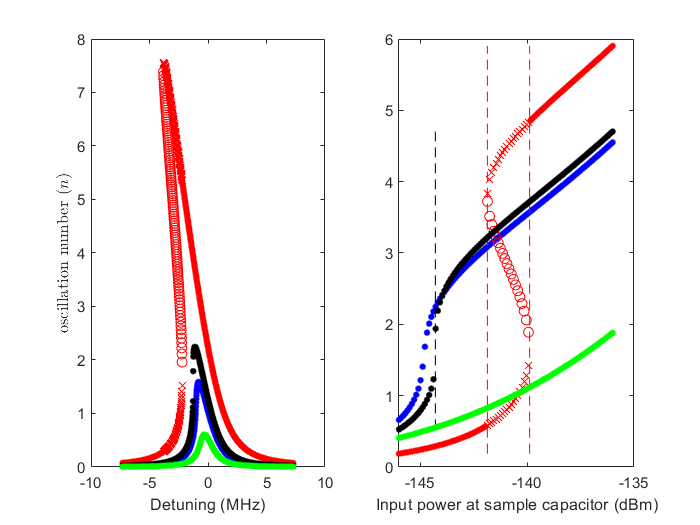

    plotting_y_1 = squeeze(amp_roots(:,check_detuning_number,1));
    plotting_y_2 = squeeze(amp_roots(:,check_detuning_number,2));
    plotting_y_3 = squeeze(amp_roots(:,check_detuning_number,3));
    
    
    monostable_root = plotting_y_1 + plotting_y_3;
    monostable_root(plotting_y_1.*plotting_y_3 ~= 0) = 0;
    bistable_root_1 = plotting_y_1;
    bistable_root_2 = plotting_y_3;
    bistable_root_1(plotting_y_1.*plotting_y_3 == 0) = 0;
    bistable_root_2(plotting_y_1.*plotting_y_3 == 0) = 0;
    plotting_x_monostable = power_input_array(:,check_detuning_number);
    plotting_x_bistable_1 = power_input_array(:,check_detuning_number);
    plotting_x_bistable_2 = power_input_array(:,check_detuning_number);
    plotting_x_monostable(monostable_root == 0) = [];
    monostable_root(monostable_root == 0) = [];
    plotting_x_bistable_1 (bistable_root_1 == 0) = [];
    bistable_root_1(bistable_root_1 == 0) = [];
    plotting_x_bistable_2(bistable_root_2 == 0) = [];
    bistable_root_2(bistable_root_2 == 0) = [];
    
    plotting_x_1 = power_input_array(:,check_detuning_number);
    plotting_x_2 = plotting_x_1;
    plotting_x_3 = plotting_x_1;
    
    plotting_x_1(plotting_y_1 == 0) = [];
    plotting_y_1(plotting_y_1 == 0) = [];
    plotting_x_2(plotting_y_2 == 0) = [];
    plotting_y_2(plotting_y_2 == 0) = [];
    plotting_x_3(plotting_y_3 == 0) = [];
    plotting_y_3(plotting_y_3 == 0) = [];
    % this plots solution 1, 2 and 3 without distinguishing between mono,
    % bi and unstable.
%     plot(plotting_x_1, plotting_y_1,'x')
%     hold on
%     plot(plotting_x_2, plotting_y_2,'o')
%     plot(plotting_x_3, plotting_y_3,'.')
    
    plot(10*log10(plotting_x_monostable*h*omega_0*1e6/1e-3), monostable_root,'r.','MarkerSize',12)
    hold on
    plot(10*log10(plotting_x_bistable_1*h*omega_0*1e6/1e-3), bistable_root_1,'rx')
    plot(10*log10(plotting_x_bistable_2*h*omega_0*1e6/1e-3), bistable_root_2,'rx')
    plot(10*log10(plotting_x_2*h*omega_0*1e6/1e-3), plotting_y_2,'ro')
    if ~isnan(bifurcation_power_1_dBm(check_detuning_number))
    plot(bifurcation_power_1_dBm(check_detuning_number)*ones(1,2), [min([monostable_root;bistable_root_1; bistable_root_2; ...
        plotting_y_2]), max([monostable_root; bistable_root_1; bistable_root_2; plotting_y_2])],'r--')
    end
    if ~isnan(bifurcation_power_2_dBm(check_detuning_number))
        plot(bifurcation_power_2_dBm(check_detuning_number)*ones(1,2), [min([monostable_root;bistable_root_1; bistable_root_2; ...
        plotting_y_2]), max([monostable_root; bistable_root_1; bistable_root_2; plotting_y_2])],'r--')
    end
    
    
%     plot(plotting_x_1, plotting_y_1,'x')
%     plot(plotting_x_2, plotting_y_2,'o')
%     plot(plotting_x_3, plotting_y_3,'.')

%     title(['All roots oscillation number for input power ' num2str(power_input_in_dBm(check_power_input) +  fridge_attenuation) 'dBm'])
    
    plotting_y_1 = squeeze(amp_roots_critical_detuning(:,1));
    plotting_y_2 = squeeze(amp_roots_critical_detuning(:,2));
    plotting_y_3 = squeeze(amp_roots_critical_detuning(:,3));
    
    
    monostable_root = plotting_y_1 + plotting_y_3;
    monostable_root(plotting_y_1.*plotting_y_3 ~= 0) = 0;
    bistable_root_1 = plotting_y_1;
    bistable_root_2 = plotting_y_3;
    bistable_root_1(plotting_y_1.*plotting_y_3 == 0) = 0;
    bistable_root_2(plotting_y_1.*plotting_y_3 == 0) = 0;
    plotting_x_monostable = power_input_in_numbers;
    plotting_x_bistable_1 = power_input_in_numbers;
    plotting_x_bistable_2 = power_input_in_numbers;
    plotting_x_monostable(monostable_root == 0) = [];
    monostable_root(monostable_root == 0) = [];
    plotting_x_bistable_1 (bistable_root_1 == 0) = [];
    bistable_root_1(bistable_root_1 == 0) = [];
    plotting_x_bistable_2(bistable_root_2 == 0) = [];
    bistable_root_2(bistable_root_2 == 0) = [];
    
    plotting_x_1 = power_input_in_numbers;
    plotting_x_2 = plotting_x_1;
    plotting_x_3 = plotting_x_1;
    
    plotting_x_1(plotting_y_1 == 0) = [];
    plotting_y_1(plotting_y_1 == 0) = [];
    plotting_x_2(plotting_y_2 == 0) = [];
    plotting_y_2(plotting_y_2 == 0) = [];
    plotting_x_3(plotting_y_3 == 0) = [];
    plotting_y_3(plotting_y_3 == 0) = [];
    % this plots solution 1, 2 and 3 without distinguishing between mono,
    % bi and unstable.
%     plot(plotting_x_1, plotting_y_1,'x')
%     hold on
%     plot(plotting_x_2, plotting_y_2,'o')
%     plot(plotting_x_3, plotting_y_3,'.')
    
    plot(10*log10(plotting_x_monostable*h*omega_0*1e6/1e-3), monostable_root,'k.','MarkerSize',12)
    hold on
    plot(10*log10(plotting_x_bistable_1*h*omega_0*1e6/1e-3), bistable_root_1,'kx')
    plot(10*log10(plotting_x_bistable_2*h*omega_0*1e6/1e-3), bistable_root_2,'kx')
    plot(10*log10(plotting_x_2*h*omega_0*1e6/1e-3), plotting_y_2,'ko')
    if ~isnan(bifurcation_power_1_dBm_critical_detuning)
    plot(bifurcation_power_1_dBm_critical_detuning*ones(1,2), [min([monostable_root; bistable_root_1; bistable_root_2; ...
        plotting_y_2]), max([monostable_root; bistable_root_1; bistable_root_2; plotting_y_2])],'k--')
    end
    if ~isnan(bifurcation_power_2_dBm_critical_detuning)
        plot(bifurcation_power_2_dBm_critical_detuning*ones(1,2), [min([monostable_root; bistable_root_1; bistable_root_2; ...
        plotting_y_2]), max([monostable_root; bistable_root_1; bistable_root_2; plotting_y_2])],'k--')
    end
    
    plotting_y_1 = squeeze(amp_roots_specific_detuning(:,1));
    plotting_y_2 = squeeze(amp_roots_specific_detuning(:,2));
    plotting_y_3 = squeeze(amp_roots_specific_detuning(:,3));
    
    
    monostable_root = plotting_y_1 + plotting_y_3;
    monostable_root(plotting_y_1.*plotting_y_3 ~= 0) = 0;
    bistable_root_1 = plotting_y_1;
    bistable_root_2 = plotting_y_3;
    bistable_root_1(plotting_y_1.*plotting_y_3 == 0) = 0;
    bistable_root_2(plotting_y_1.*plotting_y_3 == 0) = 0;
    plotting_x_monostable = power_input_in_numbers;
    plotting_x_bistable_1 = power_input_in_numbers;
    plotting_x_bistable_2 = power_input_in_numbers;
    plotting_x_monostable(monostable_root == 0) = [];
    monostable_root(monostable_root == 0) = [];
    plotting_x_bistable_1 (bistable_root_1 == 0) = [];
    bistable_root_1(bistable_root_1 == 0) = [];
    plotting_x_bistable_2(bistable_root_2 == 0) = [];
    bistable_root_2(bistable_root_2 == 0) = [];
    
    plotting_x_1 = power_input_in_numbers;
    plotting_x_2 = plotting_x_1;
    plotting_x_3 = plotting_x_1;
    
    plotting_x_1(plotting_y_1 == 0) = [];
    plotting_y_1(plotting_y_1 == 0) = [];
    plotting_x_2(plotting_y_2 == 0) = [];
    plotting_y_2(plotting_y_2 == 0) = [];
    plotting_x_3(plotting_y_3 == 0) = [];
    plotting_y_3(plotting_y_3 == 0) = [];
    
    % this plots solution 1, 2 and 3 without distinguishing between mono,
    % bi and unstable.
%     plot(plotting_x_1, plotting_y_1,'x')
%     hold on
%     plot(plotting_x_2, plotting_y_2,'o')
%     plot(plotting_x_3, plotting_y_3,'.')
    
    plot(10*log10(plotting_x_monostable*h*omega_0*1e6/1e-3), monostable_root,'g.','MarkerSize',12)
    hold on
    plot(10*log10(plotting_x_bistable_1*h*omega_0*1e6/1e-3), bistable_root_1,'gx')
    plot(10*log10(plotting_x_bistable_2*h*omega_0*1e6/1e-3), bistable_root_2,'gx')
    plot(10*log10(plotting_x_2*h*omega_0*1e6/1e-3), plotting_y_2,'go')
    if ~isnan(bifurcation_power_1_dBm_specific_detuning)
    plot(bifurcation_power_1_dBm_specific_detuning*ones(1,2), [min([monostable_root; bistable_root_1; bistable_root_2; ...
        plotting_y_2]), max([monostable_root; bistable_root_1; bistable_root_2; plotting_y_2])],'g--')
    end
    if ~isnan(bifurcation_power_2_dBm_specific_detuning)
        plot(bifurcation_power_2_dBm_specific_detuning*ones(1,2), [min([monostable_root; bistable_root_1; bistable_root_2; ...
        plotting_y_2]), max([monostable_root; bistable_root_1; bistable_root_2; plotting_y_2])],'g--')
    end
%     
%     plot(plotting_x_1, plotting_y_1,'x')
%     plot(plotting_x_2, plotting_y_2,'o')
%     plot(plotting_x_3, plotting_y_3,'.')
    hold off
    xlabel('Input power at sample capacitor (dBm)')

%     ylabel('oscillation number ($n$)','Interpreter',"latex")
    

check_detuning_number = 394

check_detuning_number = 394

check_power_input = 3

check_power_input = 3

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
plotting_y_1 = squeeze(s11(check_power_input,:,1));
plotting_y_2 = squeeze(s11(check_power_input,:,2));
plotting_y_3 = squeeze(s11(check_power_input,:,3));


monostable_root = plotting_y_1 + plotting_y_3;
monostable_root(plotting_y_1.*plotting_y_3 ~= 0) = 0;
bistable_root_1 = plotting_y_1;
bistable_root_2 = plotting_y_3;
bistable_root_1(plotting_y_1.*plotting_y_3 == 0) = 0;
bistable_root_2(plotting_y_1.*plotting_y_3 == 0) = 0;
plotting_x_monostable = detunings_array(check_power_input,:);
plotting_x_bistable_1 = detunings_array(check_power_input,:);
plotting_x_bistable_2 = detunings_array(check_power_input,:);
plotting_x_monostable(monostable_root == 0) = [];
monostable_root(monostable_root == 0) = [];
plotting_x_bistable_1 (bistable_root_1 == 0) = [];
bistable_root_1(bistable_root_1 == 0) = [];
plotting_x_bistable_2(bistable_root_2 == 0) = [];
bistable_root_2(bistable_root_2 == 0) = [];

plotting_x_1 = detunings_array(check_power_input,:);
plotting_x_2 = plotting_x_1;
plotting_x_3 = plotting_x_1;

plotting_x_1(plotting_y_1 == 0) = [];
plotting_y_1(plotting_y_1 == 0) = [];
plotting_x_2(plotting_y_2 == 0) = [];
plotting_y_2(plotting_y_2 == 0) = [];
plotting_x_3(plotting_y_3 == 0) = [];
plotting_y_3(plotting_y_3 == 0) = [];
figure
% this plots solution 1, 2 and 3 without distinguishing between mono,
% bi and unstable.
%     plot(plotting_x_1, plotting_y_1,'x')
%     hold on
%     plot(plotting_x_2, plotting_y_2,'o')
%     plot(plotting_x_3, plotting_y_3,'.')
subplot(2,1,1)
hold on
plot(plotting_x_monostable, abs(monostable_root),'b.')
plot(plotting_x_bistable_1, abs(bistable_root_1),'bx')
plot(plotting_x_bistable_2, abs(bistable_root_2),'bx')
plot(plotting_x_2, abs(plotting_y_2),'bo')
hold off
subplot(2,1,2)
hold on
plot(plotting_x_monostable, wrapTo360(180/pi*angle(monostable_root)),'b.')
plot(plotting_x_bistable_1, wrapTo360(180/pi*angle(bistable_root_1)),'bx')
plot(plotting_x_bistable_2, wrapTo360(180/pi*angle(bistable_root_2)),'bx')
plot(plotting_x_2, wrapTo360(180/pi*angle(plotting_y_2)),'bo')
hold off

check_power_input = 70

check_power_input = 70

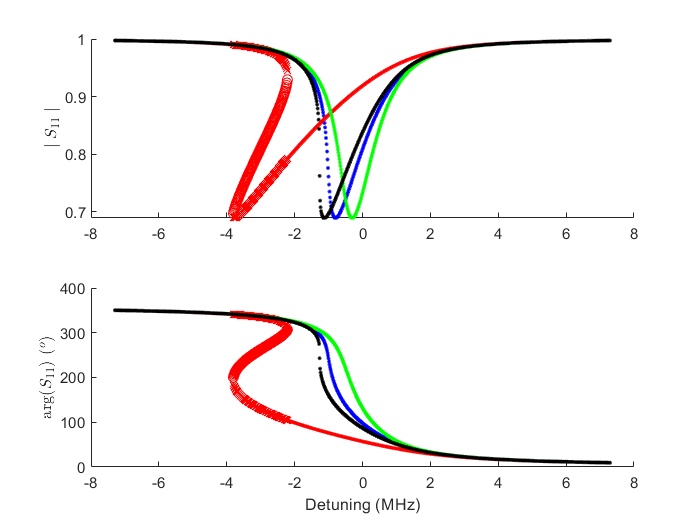

plotting_y_1 = squeeze(s11(check_power_input,:,1));
plotting_y_2 = squeeze(s11(check_power_input,:,2));
plotting_y_3 = squeeze(s11(check_power_input,:,3));
plotting_x_1 = detunings_array(check_power_input,:);
plotting_x_2 = plotting_x_1;
plotting_x_3 = plotting_x_1;

monostable_root = plotting_y_1 + plotting_y_3;
monostable_root(plotting_y_1.*plotting_y_3 ~= 0) = 0;
bistable_root_1 = plotting_y_1;
bistable_root_2 = plotting_y_3;
bistable_root_1(plotting_y_1.*plotting_y_3 == 0) = 0;
bistable_root_2(plotting_y_1.*plotting_y_3 == 0) = 0;
plotting_x_monostable = detunings_array(check_power_input,:);
plotting_x_bistable_1 = detunings_array(check_power_input,:);
plotting_x_bistable_2 = detunings_array(check_power_input,:);
plotting_x_monostable(monostable_root == 0) = [];
monostable_root(monostable_root == 0) = [];
plotting_x_bistable_1 (bistable_root_1 == 0) = [];
bistable_root_1(bistable_root_1 == 0) = [];
plotting_x_bistable_2(bistable_root_2 == 0) = [];
bistable_root_2(bistable_root_2 == 0) = [];

plotting_x_1(plotting_y_1 == 0) = [];
plotting_y_1(plotting_y_1 == 0) = [];
plotting_x_2(plotting_y_2 == 0) = [];
plotting_y_2(plotting_y_2 == 0) = [];
plotting_x_3(plotting_y_3 == 0) = [];
plotting_y_3(plotting_y_3 == 0) = [];

subplot(2,1,1)
hold on
plot(plotting_x_monostable, abs(monostable_root),'r.')
plot(plotting_x_bistable_1, abs(bistable_root_1),'rx')
plot(plotting_x_bistable_2, abs(bistable_root_2),'rx')
plot(plotting_x_2, abs(plotting_y_2),'ro')
hold off
subplot(2,1,2)
hold on
plot(plotting_x_monostable, wrapTo360(180/pi*angle(monostable_root)),'r.')
plot(plotting_x_bistable_1, wrapTo360(180/pi*angle(bistable_root_1)),'rx')
plot(plotting_x_bistable_2, wrapTo360(180/pi*angle(bistable_root_2)),'rx')
plot(plotting_x_2, wrapTo360(180/pi*angle(plotting_y_2)),'ro')
hold off

%     plot(plotting_x_1, plotting_y_1,'x')
%     plot(plotting_x_2, plotting_y_2,'o')
%     plot(plotting_x_3, plotting_y_3,'.')
%     title(['All roots oscillation number for input power ' num2str(power_input_in_dBm(check_power_input) +  fridge_attenuation) 'dBm'])

plotting_y_1 = squeeze(s11_specific_power(:,1));
plotting_y_2 = squeeze(s11_specific_power(:,2));
plotting_y_3 = squeeze(s11_specific_power(:,3));
plotting_x_1 = detunings;
plotting_x_2 = plotting_x_1;
plotting_x_3 = plotting_x_1;

monostable_root = plotting_y_1 + plotting_y_3;
monostable_root(plotting_y_1.*plotting_y_3 ~= 0) = 0;
bistable_root_1 = plotting_y_1;
bistable_root_2 = plotting_y_3;
bistable_root_1(plotting_y_1.*plotting_y_3 == 0) = 0;
bistable_root_2(plotting_y_1.*plotting_y_3 == 0) = 0;
plotting_x_monostable = detunings;
plotting_x_bistable_1 = detunings;
plotting_x_bistable_2 = detunings;
plotting_x_monostable(monostable_root == 0) = [];
monostable_root(monostable_root == 0) = [];
plotting_x_bistable_1 (bistable_root_1 == 0) = [];
bistable_root_1(bistable_root_1 == 0) = [];
plotting_x_bistable_2(bistable_root_2 == 0) = [];
bistable_root_2(bistable_root_2 == 0) = [];

plotting_x_1(plotting_y_1 == 0) = [];
plotting_y_1(plotting_y_1 == 0) = [];
plotting_x_2(plotting_y_2 == 0) = [];
plotting_y_2(plotting_y_2 == 0) = [];
plotting_x_3(plotting_y_3 == 0) = [];
plotting_y_3(plotting_y_3 == 0) = [];

subplot(2,1,1)
hold on
plot(plotting_x_monostable, abs(monostable_root),'g.')
plot(plotting_x_bistable_1, abs(bistable_root_1),'gx')
plot(plotting_x_bistable_2, abs(bistable_root_2),'gx')
plot(plotting_x_2, abs(plotting_y_2),'go')
hold off
subplot(2,1,2)
hold on
plot(plotting_x_monostable, wrapTo360(180/pi*angle(monostable_root)),'g.')
plot(plotting_x_bistable_1, wrapTo360(180/pi*angle(bistable_root_1)),'gx')
plot(plotting_x_bistable_2, wrapTo360(180/pi*angle(bistable_root_2)),'gx')
plot(plotting_x_2, wrapTo360(180/pi*angle(plotting_y_2)),'go')
hold off

plotting_y_1 = squeeze(s11_critical_power(:,1));
plotting_y_2 = squeeze(s11_critical_power(:,2));
plotting_y_3 = squeeze(s11_critical_power(:,3));
plotting_x_1 = detunings;
plotting_x_2 = plotting_x_1;
plotting_x_3 = plotting_x_1;

monostable_root = plotting_y_1 + plotting_y_3;
monostable_root(plotting_y_1.*plotting_y_3 ~= 0) = 0;
bistable_root_1 = plotting_y_1;
bistable_root_2 = plotting_y_3;
bistable_root_1(plotting_y_1.*plotting_y_3 == 0) = 0;
bistable_root_2(plotting_y_1.*plotting_y_3 == 0) = 0;
plotting_x_monostable = detunings;
plotting_x_bistable_1 = detunings;
plotting_x_bistable_2 = detunings;
plotting_x_monostable(monostable_root == 0) = [];
monostable_root(monostable_root == 0) = [];
plotting_x_bistable_1 (bistable_root_1 == 0) = [];
bistable_root_1(bistable_root_1 == 0) = [];
plotting_x_bistable_2(bistable_root_2 == 0) = [];
bistable_root_2(bistable_root_2 == 0) = [];

plotting_x_1(plotting_y_1 == 0) = [];
plotting_y_1(plotting_y_1 == 0) = [];
plotting_x_2(plotting_y_2 == 0) = [];
plotting_y_2(plotting_y_2 == 0) = [];
plotting_x_3(plotting_y_3 == 0) = [];
plotting_y_3(plotting_y_3 == 0) = [];

subplot(2,1,1)
hold on
plot(plotting_x_monostable, abs(monostable_root),'k.')
plot(plotting_x_bistable_1, abs(bistable_root_1),'kx')
plot(plotting_x_bistable_2, abs(bistable_root_2),'kx')
plot(plotting_x_2, abs(plotting_y_2),'ko')
hold off
ylabel('$\mid S_{11} \mid$', 'Interpreter',"latex")
subplot(2,1,2)
hold on
plot(plotting_x_monostable, wrapTo360(180/pi*angle(monostable_root)),'k.')
plot(plotting_x_bistable_1, wrapTo360(180/pi*angle(bistable_root_1)),'kx')
plot(plotting_x_bistable_2, wrapTo360(180/pi*angle(bistable_root_2)),'kx')
plot(plotting_x_2, wrapTo360(180/pi*angle(plotting_y_2)),'ko')
hold off
xlabel('Detuning (MHz)')
ylabel('arg($S_{11}$) ($^o$)', 'Interpreter',"latex")

%     
%     plot(plotting_x_1, plotting_y_1,'x')
%     plot(plotting_x_2, plotting_y_2,'o')
%     plot(plotting_x_3, plotting_y_3,'.')

check_detuning_number = 421

check_detuning_number = 421

check_power_input = 3

check_power_input = 3

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
plotting_y_1 = squeeze(s11(:,check_detuning_number, 1));
plotting_y_2 = squeeze(s11(:,check_detuning_number,2));
plotting_y_3 = squeeze(s11(:,check_detuning_number,3));


monostable_root = plotting_y_1 + plotting_y_3;
monostable_root(plotting_y_1.*plotting_y_3 ~= 0) = 0;
bistable_root_1 = plotting_y_1;
bistable_root_2 = plotting_y_3;
bistable_root_1(plotting_y_1.*plotting_y_3 == 0) = 0;
bistable_root_2(plotting_y_1.*plotting_y_3 == 0) = 0;
plotting_x_monostable = power_input_array(:,check_detuning_number);
plotting_x_bistable_1 = power_input_array(:,check_detuning_number);
plotting_x_bistable_2 = power_input_array(:,check_detuning_number);
plotting_x_monostable(monostable_root == 0) = [];
monostable_root(monostable_root == 0) = [];
plotting_x_bistable_1 (bistable_root_1 == 0) = [];
bistable_root_1(bistable_root_1 == 0) = [];
plotting_x_bistable_2(bistable_root_2 == 0) = [];
bistable_root_2(bistable_root_2 == 0) = [];

plotting_x_1 = power_input_array(:,check_detuning_number);
plotting_x_2 = plotting_x_1;
plotting_x_3 = plotting_x_1;

plotting_x_1(plotting_y_1 == 0) = [];
plotting_y_1(plotting_y_1 == 0) = [];
plotting_x_2(plotting_y_2 == 0) = [];
plotting_y_2(plotting_y_2 == 0) = [];
plotting_x_3(plotting_y_3 == 0) = [];
plotting_y_3(plotting_y_3 == 0) = [];
figure
% this plots solution 1, 2 and 3 without distinguishing between mono,
% bi and unstable.
%     plot(plotting_x_1, plotting_y_1,'x')
%     hold on
%     plot(plotting_x_2, plotting_y_2,'o')
%     plot(plotting_x_3, plotting_y_3,'.')
subplot(2,1,1)
hold on
plot(10*log10(plotting_x_monostable*h*omega_0*1e6/1e-3), abs(monostable_root),'b.', 'MarkerSize', 12)
plot(10*log10(plotting_x_bistable_1*h*omega_0*1e6/1e-3), abs(bistable_root_1),'bx')
plot(10*log10(plotting_x_bistable_2*h*omega_0*1e6/1e-3), abs(bistable_root_2),'bx')
plot(10*log10(plotting_x_2*h*omega_0*1e6/1e-3), abs(plotting_y_2),'bo')
if ~isnan(bifurcation_power_1_dBm(check_detuning_number))
    plot(bifurcation_power_1_dBm(check_detuning_number)*ones(1,2), [min([abs(monostable_root); abs(bistable_root_1); abs(bistable_root_2); ...
        abs(plotting_y_2)]), max([abs(monostable_root); abs(bistable_root_1); abs(bistable_root_2); abs(plotting_y_2)])],'b--')
end
if ~isnan(bifurcation_power_2_dBm(check_detuning_number))
    plot(bifurcation_power_2_dBm(check_detuning_number)*ones(1,2), [min([abs(monostable_root); abs(bistable_root_1); abs(bistable_root_2); ...
        abs(plotting_y_2)]), max([abs(monostable_root); abs(bistable_root_1); abs(bistable_root_2); abs(plotting_y_2)])],'b--')
end

hold off
subplot(2,1,2)
hold on
plot(10*log10(plotting_x_monostable*h*omega_0*1e6/1e-3), wrapTo360(180/pi*angle(monostable_root)),'b.', 'MarkerSize', 12)
plot(10*log10(plotting_x_bistable_1*h*omega_0*1e6/1e-3), wrapTo360(180/pi*angle(bistable_root_1)),'bx')
plot(10*log10(plotting_x_bistable_2*h*omega_0*1e6/1e-3), wrapTo360(180/pi*angle(bistable_root_2)),'bx')
plot(10*log10(plotting_x_2*h*omega_0*1e6/1e-3), wrapTo360(180/pi*angle(plotting_y_2)),'bo')
if ~isnan(bifurcation_power_1_dBm(check_detuning_number))
    plot(bifurcation_power_1_dBm(check_detuning_number)*ones(1,2), [min([wrapTo360(180/pi*angle(monostable_root)); wrapTo360(180/pi*angle(bistable_root_1)); wrapTo360(180/pi*angle(bistable_root_2)); ...
        wrapTo360(180/pi*angle(plotting_y_2))]), max([wrapTo360(180/pi*angle(monostable_root)); wrapTo360(180/pi*angle(bistable_root_1)); wrapTo360(180/pi*angle(bistable_root_2)); wrapTo360(180/pi*angle(plotting_y_2))])],'b--')
end
if ~isnan(bifurcation_power_2_dBm(check_detuning_number))
    plot(bifurcation_power_2_dBm(check_detuning_number)*ones(1,2), [min([wrapTo360(180/pi*angle(monostable_root)); wrapTo360(180/pi*angle(bistable_root_1)); wrapTo360(180/pi*angle(bistable_root_2)); ...
        wrapTo360(180/pi*angle(plotting_y_2))]), max([wrapTo360(180/pi*angle(monostable_root)); wrapTo360(180/pi*angle(bistable_root_1)); wrapTo360(180/pi*angle(bistable_root_2)); wrapTo360(180/pi*angle(plotting_y_2))])],'b--')
end
hold off

check_detuning_number = 361

check_detuning_number = 361

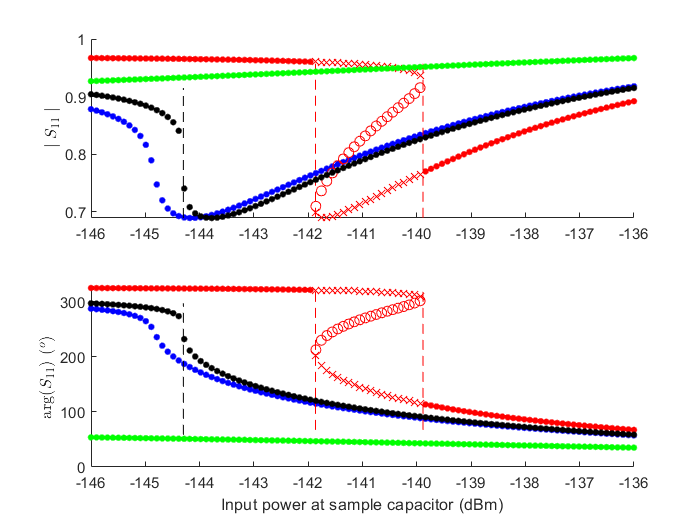

plotting_y_1 = squeeze(s11(:,check_detuning_number, 1));
plotting_y_2 = squeeze(s11(:,check_detuning_number,2));
plotting_y_3 = squeeze(s11(:,check_detuning_number,3));


monostable_root = plotting_y_1 + plotting_y_3;
monostable_root(plotting_y_1.*plotting_y_3 ~= 0) = 0;
bistable_root_1 = plotting_y_1;
bistable_root_2 = plotting_y_3;
bistable_root_1(plotting_y_1.*plotting_y_3 == 0) = 0;
bistable_root_2(plotting_y_1.*plotting_y_3 == 0) = 0;
plotting_x_monostable = power_input_array(:,check_detuning_number);
plotting_x_bistable_1 = power_input_array(:,check_detuning_number);
plotting_x_bistable_2 = power_input_array(:,check_detuning_number);
plotting_x_monostable(monostable_root == 0) = [];
monostable_root(monostable_root == 0) = [];
plotting_x_bistable_1 (bistable_root_1 == 0) = [];
bistable_root_1(bistable_root_1 == 0) = [];
plotting_x_bistable_2(bistable_root_2 == 0) = [];
bistable_root_2(bistable_root_2 == 0) = [];

plotting_x_1 = power_input_array(:,check_detuning_number);
plotting_x_2 = plotting_x_1;
plotting_x_3 = plotting_x_1;

plotting_x_1(plotting_y_1 == 0) = [];
plotting_y_1(plotting_y_1 == 0) = [];
plotting_x_2(plotting_y_2 == 0) = [];
plotting_y_2(plotting_y_2 == 0) = [];
plotting_x_3(plotting_y_3 == 0) = [];
plotting_y_3(plotting_y_3 == 0) = [];
% this plots solution 1, 2 and 3 without distinguishing between mono,
% bi and unstable.
%     plot(plotting_x_1, plotting_y_1,'x')
%     hold on
%     plot(plotting_x_2, plotting_y_2,'o')
%     plot(plotting_x_3, plotting_y_3,'.')
subplot(2,1,1)
hold on
plot(10*log10(plotting_x_monostable*h*omega_0*1e6/1e-3), abs(monostable_root),'r.', 'MarkerSize', 12)
plot(10*log10(plotting_x_bistable_1*h*omega_0*1e6/1e-3), abs(bistable_root_1),'rx')
plot(10*log10(plotting_x_bistable_2*h*omega_0*1e6/1e-3), abs(bistable_root_2),'rx')
plot(10*log10(plotting_x_2*h*omega_0*1e6/1e-3), abs(plotting_y_2),'ro')
if ~isnan(bifurcation_power_1_dBm(check_detuning_number))
    plot(bifurcation_power_1_dBm(check_detuning_number)*ones(1,2), [min([abs(monostable_root); abs(bistable_root_1); abs(bistable_root_2); ...
        abs(plotting_y_2)]), max([abs(monostable_root); abs(bistable_root_1); abs(bistable_root_2); abs(plotting_y_2)])],'r--')
end
if ~isnan(bifurcation_power_2_dBm(check_detuning_number))
    plot(bifurcation_power_2_dBm(check_detuning_number)*ones(1,2), [min([abs(monostable_root); abs(bistable_root_1); abs(bistable_root_2); ...
        abs(plotting_y_2)]), max([abs(monostable_root); abs(bistable_root_1); abs(bistable_root_2); abs(plotting_y_2)])],'r--')
end
hold off
subplot(2,1,2)
hold on
plot(10*log10(plotting_x_monostable*h*omega_0*1e6/1e-3), wrapTo360(180/pi*angle(monostable_root)),'r.', 'MarkerSize', 12)
plot(10*log10(plotting_x_bistable_1*h*omega_0*1e6/1e-3), wrapTo360(180/pi*angle(bistable_root_1)),'rx')
plot(10*log10(plotting_x_bistable_2*h*omega_0*1e6/1e-3), wrapTo360(180/pi*angle(bistable_root_2)),'rx')
plot(10*log10(plotting_x_2*h*omega_0*1e6/1e-3), wrapTo360(180/pi*angle(plotting_y_2)),'ro')
if ~isnan(bifurcation_power_1_dBm(check_detuning_number))
    plot(bifurcation_power_1_dBm(check_detuning_number)*ones(1,2), [min([wrapTo360(180/pi*angle(monostable_root)); wrapTo360(180/pi*angle(bistable_root_1)); wrapTo360(180/pi*angle(bistable_root_2)); ...
        wrapTo360(180/pi*angle(plotting_y_2))]), max([wrapTo360(180/pi*angle(monostable_root)); wrapTo360(180/pi*angle(bistable_root_1)); wrapTo360(180/pi*angle(bistable_root_2)); wrapTo360(180/pi*angle(plotting_y_2))])],'r--')
end
if ~isnan(bifurcation_power_2_dBm(check_detuning_number))
    plot(bifurcation_power_2_dBm(check_detuning_number)*ones(1,2), [min([wrapTo360(180/pi*angle(monostable_root)); wrapTo360(180/pi*angle(bistable_root_1)); wrapTo360(180/pi*angle(bistable_root_2)); ...
        wrapTo360(180/pi*angle(plotting_y_2))]), max([wrapTo360(180/pi*angle(monostable_root)); wrapTo360(180/pi*angle(bistable_root_1)); wrapTo360(180/pi*angle(bistable_root_2)); wrapTo360(180/pi*angle(plotting_y_2))])],'r--')
end
hold off

%     plot(plotting_x_1, plotting_y_1,'x')
%     plot(plotting_x_2, plotting_y_2,'o')
%     plot(plotting_x_3, plotting_y_3,'.')
%     title(['All roots oscillation number for input power ' num2str(power_input_in_dBm(check_power_input) +  fridge_attenuation) 'dBm'])

plotting_y_1 = squeeze(s11_critical_detuning(:, 1));
plotting_y_2 = squeeze(s11_critical_detuning(:,2));
plotting_y_3 = squeeze(s11_critical_detuning(:,3));


monostable_root = plotting_y_1 + plotting_y_3;
monostable_root(plotting_y_1.*plotting_y_3 ~= 0) = 0;
bistable_root_1 = plotting_y_1;
bistable_root_2 = plotting_y_3;
bistable_root_1(plotting_y_1.*plotting_y_3 == 0) = 0;
bistable_root_2(plotting_y_1.*plotting_y_3 == 0) = 0;
plotting_x_monostable = power_input_array(:,check_detuning_number);
plotting_x_bistable_1 = power_input_array(:,check_detuning_number);
plotting_x_bistable_2 = power_input_array(:,check_detuning_number);
plotting_x_monostable(monostable_root == 0) = [];
monostable_root(monostable_root == 0) = [];
plotting_x_bistable_1 (bistable_root_1 == 0) = [];
bistable_root_1(bistable_root_1 == 0) = [];
plotting_x_bistable_2(bistable_root_2 == 0) = [];
bistable_root_2(bistable_root_2 == 0) = [];

plotting_x_1 = power_input_in_numbers;
plotting_x_2 = plotting_x_1;
plotting_x_3 = plotting_x_1;

plotting_x_1(plotting_y_1 == 0) = [];
plotting_y_1(plotting_y_1 == 0) = [];
plotting_x_2(plotting_y_2 == 0) = [];
plotting_y_2(plotting_y_2 == 0) = [];
plotting_x_3(plotting_y_3 == 0) = [];
plotting_y_3(plotting_y_3 == 0) = [];
% this plots solution 1, 2 and 3 without distinguishing between mono,
% bi and unstable.
%     plot(plotting_x_1, plotting_y_1,'x')
%     hold on
%     plot(plotting_x_2, plotting_y_2,'o')
%     plot(plotting_x_3, plotting_y_3,'.')
subplot(2,1,1)
hold on
plot(10*log10(plotting_x_monostable*h*omega_0*1e6/1e-3), abs(monostable_root),'k.', 'MarkerSize', 12)
plot(10*log10(plotting_x_bistable_1*h*omega_0*1e6/1e-3), abs(bistable_root_1),'kx')
plot(10*log10(plotting_x_bistable_2*h*omega_0*1e6/1e-3), abs(bistable_root_2),'kx')
plot(10*log10(plotting_x_2*h*omega_0*1e6/1e-3), abs(plotting_y_2),'ko')
if ~isnan(bifurcation_power_1_dBm_critical_detuning)
    plot(bifurcation_power_1_dBm_critical_detuning*ones(1,2), [min([abs(monostable_root); abs(bistable_root_1); abs(bistable_root_2); ...
        abs(plotting_y_2)]), max([abs(monostable_root); abs(bistable_root_1); abs(bistable_root_2); abs(plotting_y_2)])],'k--')
end
if ~isnan(bifurcation_power_2_dBm_critical_detuning)
    plot(bifurcation_power_2_dBm_critical_detuning*ones(1,2), [min([abs(monostable_root); abs(bistable_root_1); abs(bistable_root_2); ...
        abs(plotting_y_2)]), max([abs(monostable_root); abs(bistable_root_1); abs(bistable_root_2); abs(plotting_y_2)])],'k--')
end
hold off
subplot(2,1,2)
hold on
plot(10*log10(plotting_x_monostable*h*omega_0*1e6/1e-3), wrapTo360(180/pi*angle(monostable_root)),'k.', 'MarkerSize', 12)
plot(10*log10(plotting_x_bistable_1*h*omega_0*1e6/1e-3), wrapTo360(180/pi*angle(bistable_root_1)),'kx')
plot(10*log10(plotting_x_bistable_2*h*omega_0*1e6/1e-3), wrapTo360(180/pi*angle(bistable_root_2)),'kx')
plot(10*log10(plotting_x_2*h*omega_0*1e6/1e-3), wrapTo360(180/pi*angle(plotting_y_2)),'ko')
if ~isnan(bifurcation_power_1_dBm_critical_detuning)
    plot(bifurcation_power_1_dBm_critical_detuning*ones(1,2), [min([wrapTo360(180/pi*angle(monostable_root)); wrapTo360(180/pi*angle(bistable_root_1)); wrapTo360(180/pi*angle(bistable_root_2)); ...
        wrapTo360(180/pi*angle(plotting_y_2))]), max([wrapTo360(180/pi*angle(monostable_root)); wrapTo360(180/pi*angle(bistable_root_1)); wrapTo360(180/pi*angle(bistable_root_2)); wrapTo360(180/pi*angle(plotting_y_2))])],'k--')
end
if ~isnan(bifurcation_power_2_dBm_critical_detuning)
    plot(bifurcation_power_2_dBm_critical_detuning*ones(1,2), [min([wrapTo360(180/pi*angle(monostable_root)); wrapTo360(180/pi*angle(bistable_root_1)); wrapTo360(180/pi*angle(bistable_root_2)); ...
        wrapTo360(180/pi*angle(plotting_y_2))]), max([wrapTo360(180/pi*angle(monostable_root)); wrapTo360(180/pi*angle(bistable_root_1)); wrapTo360(180/pi*angle(bistable_root_2)); wrapTo360(180/pi*angle(plotting_y_2))])],'k--')
end
hold off

plotting_y_1 = squeeze(s11_specific_detuning(:, 1));
plotting_y_2 = squeeze(s11_specific_detuning(:,2));
plotting_y_3 = squeeze(s11_specific_detuning(:,3));


monostable_root = plotting_y_1 + plotting_y_3;
monostable_root(plotting_y_1.*plotting_y_3 ~= 0) = 0;
bistable_root_1 = plotting_y_1;
bistable_root_2 = plotting_y_3;
bistable_root_1(plotting_y_1.*plotting_y_3 == 0) = 0;
bistable_root_2(plotting_y_1.*plotting_y_3 == 0) = 0;
plotting_x_monostable = power_input_array(:,check_detuning_number);
plotting_x_bistable_1 = power_input_array(:,check_detuning_number);
plotting_x_bistable_2 = power_input_array(:,check_detuning_number);
plotting_x_monostable(monostable_root == 0) = [];
monostable_root(monostable_root == 0) = [];
plotting_x_bistable_1 (bistable_root_1 == 0) = [];
bistable_root_1(bistable_root_1 == 0) = [];
plotting_x_bistable_2(bistable_root_2 == 0) = [];
bistable_root_2(bistable_root_2 == 0) = [];

plotting_x_1 = power_input_in_numbers;
plotting_x_2 = plotting_x_1;
plotting_x_3 = plotting_x_1;

plotting_x_1(plotting_y_1 == 0) = [];
plotting_y_1(plotting_y_1 == 0) = [];
plotting_x_2(plotting_y_2 == 0) = [];
plotting_y_2(plotting_y_2 == 0) = [];
plotting_x_3(plotting_y_3 == 0) = [];
plotting_y_3(plotting_y_3 == 0) = [];
% this plots solution 1, 2 and 3 without distinguishing between mono,
% bi and unstable.
%     plot(plotting_x_1, plotting_y_1,'x')
%     hold on
%     plot(plotting_x_2, plotting_y_2,'o')
%     plot(plotting_x_3, plotting_y_3,'.')
subplot(2,1,1)
hold on
plot(10*log10(plotting_x_monostable*h*omega_0*1e6/1e-3), abs(monostable_root),'g.', 'MarkerSize', 12)
plot(10*log10(plotting_x_bistable_1*h*omega_0*1e6/1e-3), abs(bistable_root_1),'gx')
plot(10*log10(plotting_x_bistable_2*h*omega_0*1e6/1e-3), abs(bistable_root_2),'gx')
plot(10*log10(plotting_x_2*h*omega_0*1e6/1e-3), abs(plotting_y_2),'go')
if ~isnan(bifurcation_power_1_dBm_specific_detuning)
    plot(bifurcation_power_1_dBm_specific_detuning*ones(1,2), [min([abs(monostable_root); abs(bistable_root_1); abs(bistable_root_2); ...
        abs(plotting_y_2)]), max([abs(monostable_root); abs(bistable_root_1); abs(bistable_root_2); abs(plotting_y_2)])],'g--')
end
if ~isnan(bifurcation_power_2_dBm_specific_detuning)
    plot(bifurcation_power_2_dBm_specific_detuning*ones(1,2), [min([abs(monostable_root); abs(bistable_root_1); abs(bistable_root_2); ...
        abs(plotting_y_2)]), max([abs(monostable_root); abs(bistable_root_1); abs(bistable_root_2); abs(plotting_y_2)])],'g--')
end
hold off
ylabel('$ \mid S_{11} \mid$', 'Interpreter',"latex")
subplot(2,1,2)
hold on
plot(10*log10(plotting_x_monostable*h*omega_0*1e6/1e-3), wrapTo360(180/pi*angle(monostable_root)),'g.', 'MarkerSize', 12)
plot(10*log10(plotting_x_bistable_1*h*omega_0*1e6/1e-3), wrapTo360(180/pi*angle(bistable_root_1)),'gx')
plot(10*log10(plotting_x_bistable_2*h*omega_0*1e6/1e-3), wrapTo360(180/pi*angle(bistable_root_2)),'gx')
plot(10*log10(plotting_x_2*h*omega_0*1e6/1e-3), wrapTo360(180/pi*angle(plotting_y_2)),'go')
if ~isnan(bifurcation_power_1_dBm_specific_detuning)
    plot(bifurcation_power_1_dBm_specific_detuning*ones(1,2), [min([wrapTo360(180/pi*angle(monostable_root)); wrapTo360(180/pi*angle(bistable_root_1)); wrapTo360(180/pi*angle(bistable_root_2)); ...
        wrapTo360(180/pi*angle(plotting_y_2))]), max([wrapTo360(180/pi*angle(monostable_root)); wrapTo360(180/pi*angle(bistable_root_1)); wrapTo360(180/pi*angle(bistable_root_2)); wrapTo360(180/pi*angle(plotting_y_2))])],'g--')
end
if ~isnan(bifurcation_power_2_dBm_specific_detuning)
    plot(bifurcation_power_2_dBm_specific_detuning*ones(1,2), [min([wrapTo360(180/pi*angle(monostable_root)); wrapTo360(180/pi*angle(bistable_root_1)); wrapTo360(180/pi*angle(bistable_root_2)); ...
        wrapTo360(180/pi*angle(plotting_y_2))]), max([wrapTo360(180/pi*angle(monostable_root)); wrapTo360(180/pi*angle(bistable_root_1)); wrapTo360(180/pi*angle(bistable_root_2)); wrapTo360(180/pi*angle(plotting_y_2))])],'g--')
end
hold off

xlabel('Input power at sample capacitor (dBm)')
ylabel('arg($S_{11}$) ($^o$)', 'Interpreter',"latex")

check_detuning_number = 421

check_detuning_number = 421

check_power_input = 3

check_power_input = 3

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
plotting_y_1_forward = squeeze(main_s11_forward_power(:,check_detuning_number));
plotting_y_1_reverse = squeeze(main_s11_reverse_power(:,check_detuning_number));
plotting_x_1 = power_input_array(:,check_detuning_number);

figure
% this plots solution 1, 2 and 3 without distinguishing between mono,
% bi and unstable.
%     plot(plotting_x_1, plotting_y_1,'x')
%     hold on
%     plot(plotting_x_2, plotting_y_2,'o')
%     plot(plotting_x_3, plotting_y_3,'.')
subplot(2,1,1)
hold on
plot(10*log10(plotting_x_1*h*omega_0*1e6/1e-3), abs(plotting_y_1_forward),'r:')
plot(10*log10(plotting_x_1*h*omega_0*1e6/1e-3), abs(plotting_y_1_reverse),'b:')
hold off
subplot(2,1,2)
hold on
plot(10*log10(plotting_x_1*h*omega_0*1e6/1e-3), wrapTo360(180/pi*angle(plotting_y_1_forward)),'r:')
plot(10*log10(plotting_x_1*h*omega_0*1e6/1e-3), wrapTo360(180/pi*angle(plotting_y_1_reverse)),'b:')
hold off

check_detuning_number = 361

check_detuning_number = 361

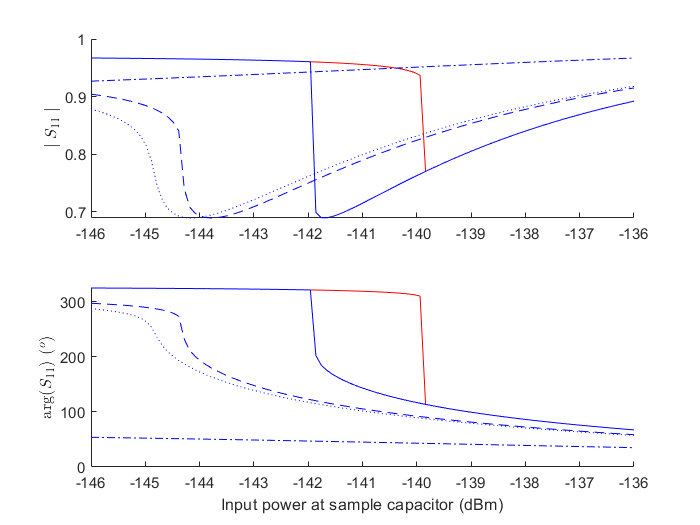

plotting_y_1_forward = squeeze(main_s11_forward_power(:,check_detuning_number));
plotting_y_1_reverse = squeeze(main_s11_reverse_power(:,check_detuning_number));
plotting_x_1 = power_input_array(:,check_detuning_number);

% this plots solution 1, 2 and 3 without distinguishing between mono,
% bi and unstable.
%     plot(plotting_x_1, plotting_y_1,'x')
%     hold on
%     plot(plotting_x_2, plotting_y_2,'o')
%     plot(plotting_x_3, plotting_y_3,'.')
subplot(2,1,1)
hold on
plot(10*log10(plotting_x_1*h*omega_0*1e6/1e-3), abs(plotting_y_1_forward),'r')
plot(10*log10(plotting_x_1*h*omega_0*1e6/1e-3), abs(plotting_y_1_reverse),'b')
hold off
subplot(2,1,2)
hold on
plot(10*log10(plotting_x_1*h*omega_0*1e6/1e-3), wrapTo360(180/pi*angle(plotting_y_1_forward)),'r')
plot(10*log10(plotting_x_1*h*omega_0*1e6/1e-3), wrapTo360(180/pi*angle(plotting_y_1_reverse)),'b')
hold off

plotting_y_1_forward = squeeze(main_s11_forward_critical_detuning);
plotting_y_1_reverse = squeeze(main_s11_reverse_critical_detuning);
plotting_x_1 = power_input_in_numbers;

subplot(2,1,1)
hold on
plot(10*log10(plotting_x_1*h*omega_0*1e6/1e-3), abs(plotting_y_1_forward),'r--')
plot(10*log10(plotting_x_1*h*omega_0*1e6/1e-3), abs(plotting_y_1_reverse),'b--')
hold off
subplot(2,1,2)
hold on
plot(10*log10(plotting_x_1*h*omega_0*1e6/1e-3), wrapTo360(180/pi*angle(plotting_y_1_forward)),'r--')
plot(10*log10(plotting_x_1*h*omega_0*1e6/1e-3), wrapTo360(180/pi*angle(plotting_y_1_reverse)),'b--')
hold off

plotting_y_1_forward = squeeze(main_s11_forward_specific_detuning);
plotting_y_1_reverse = squeeze(main_s11_forward_specific_detuning);
plotting_x_1 = power_input_in_numbers;

subplot(2,1,1)
hold on
plot(10*log10(plotting_x_1*h*omega_0*1e6/1e-3), abs(plotting_y_1_forward),'r-.')
plot(10*log10(plotting_x_1*h*omega_0*1e6/1e-3), abs(plotting_y_1_reverse),'b-.')
hold off
ylabel('$ \mid S_{11} \mid$', 'Interpreter',"latex")
subplot(2,1,2)
hold on
plot(10*log10(plotting_x_1*h*omega_0*1e6/1e-3), wrapTo360(180/pi*angle(plotting_y_1_forward)),'r-.')
plot(10*log10(plotting_x_1*h*omega_0*1e6/1e-3), wrapTo360(180/pi*angle(plotting_y_1_reverse)),'b-.')
hold off


xlabel('Input power at sample capacitor (dBm)')
ylabel('arg($S_{11}$) ($^o$)', 'Interpreter',"latex")

check_detuning_number = 421

check_detuning_number = 421

check_power_input = 3

check_power_input = 3

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
plotting_y_1_forward = squeeze(main_s11_forward(check_power_input,:));
plotting_y_1_reverse = squeeze(main_s11_reverse(check_power_input,:));
plotting_x_1 = detunings_array(check_power_input,:);

figure
% this plots solution 1, 2 and 3 without distinguishing between mono,
% bi and unstable.
%     plot(plotting_x_1, plotting_y_1,'x')
%     hold on
%     plot(plotting_x_2, plotting_y_2,'o')
%     plot(plotting_x_3, plotting_y_3,'.')
subplot(2,1,1)
hold on
plot(plotting_x_1, abs(plotting_y_1_forward),'r')
plot(plotting_x_1, abs(plotting_y_1_reverse),'b')
hold off
subplot(2,1,2)
hold on
plot(plotting_x_1, wrapTo180(180/pi*angle(plotting_y_1_forward)),'r')
plot(plotting_x_1, wrapTo180(180/pi*angle(plotting_y_1_reverse)),'b')
hold off

check_power_input = 70

check_power_input = 70

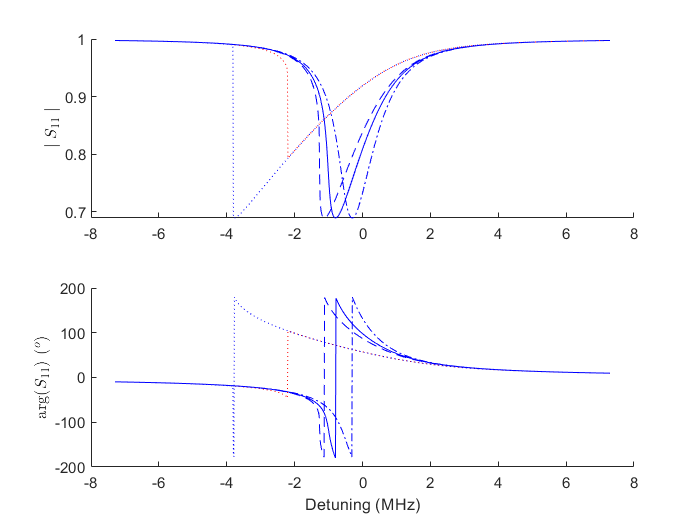

plotting_y_1_forward = squeeze(main_s11_forward(check_power_input,:));
plotting_y_1_reverse = squeeze(main_s11_reverse(check_power_input,:));
plotting_x_1 = detunings_array(check_power_input,:);

% this plots solution 1, 2 and 3 without distinguishing between mono,
% bi and unstable.
%     plot(plotting_x_1, plotting_y_1,'x')
%     hold on
%     plot(plotting_x_2, plotting_y_2,'o')
%     plot(plotting_x_3, plotting_y_3,'.')
subplot(2,1,1)
hold on
plot(plotting_x_1, abs(plotting_y_1_forward),'r:')
plot(plotting_x_1, abs(plotting_y_1_reverse),'b:')
hold off
subplot(2,1,2)
hold on
plot(plotting_x_1, wrapTo180(180/pi*angle(plotting_y_1_forward)),'r:')
plot(plotting_x_1, wrapTo180(180/pi*angle(plotting_y_1_reverse)),'b:')
hold off

plotting_y_1_forward = squeeze(main_s11_forward_critical_power);
plotting_y_1_reverse = squeeze(main_s11_reverse_critical_power);
plotting_x_1 = detunings_array(check_power_input,:);

% this plots solution 1, 2 and 3 without distinguishing between mono,
% bi and unstable.
%     plot(plotting_x_1, plotting_y_1,'x')
%     hold on
%     plot(plotting_x_2, plotting_y_2,'o')
%     plot(plotting_x_3, plotting_y_3,'.')
subplot(2,1,1)
hold on
plot(plotting_x_1, abs(plotting_y_1_forward),'r--')
plot(plotting_x_1, abs(plotting_y_1_reverse),'b--')
hold off
subplot(2,1,2)
hold on
plot(plotting_x_1, wrapTo180(180/pi*angle(plotting_y_1_forward)),'r--')
plot(plotting_x_1, wrapTo180(180/pi*angle(plotting_y_1_reverse)),'b--')
hold off

plotting_y_1_forward = squeeze(main_s11_forward_specific_power);
plotting_y_1_reverse = squeeze(main_s11_reverse_specific_power);
plotting_x_1 = detunings_array(check_power_input,:);

% this plots solution 1, 2 and 3 without distinguishing between mono,
% bi and unstable.
%     plot(plotting_x_1, plotting_y_1,'x')
%     hold on
%     plot(plotting_x_2, plotting_y_2,'o')
%     plot(plotting_x_3, plotting_y_3,'.')
subplot(2,1,1)
hold on
plot(plotting_x_1, abs(plotting_y_1_forward),'r-.')
plot(plotting_x_1, abs(plotting_y_1_reverse),'b-.')
hold off
ylabel('$ \mid S_{11} \mid$', 'Interpreter',"latex")
subplot(2,1,2)
hold on
plot(plotting_x_1, wrapTo180(180/pi*angle(plotting_y_1_forward)),'r-.')
plot(plotting_x_1, wrapTo180(180/pi*angle(plotting_y_1_reverse)),'b-.')
hold off

xlabel('Detuning (MHz)')
ylabel('arg($S_{11}$) ($^o$)', 'Interpreter',"latex")

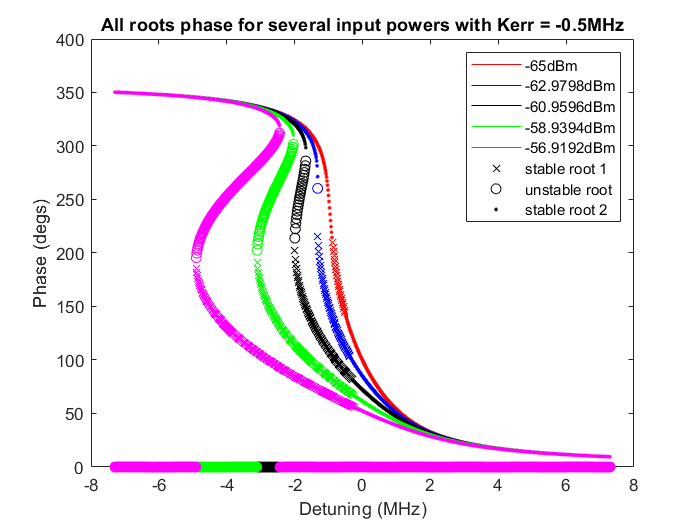

    figure
    color_array = ['r', 'b', 'k', 'g', 'm'];
    i = 1;
    j = 1;
    while i<100
        detunings_array_1 = detunings_array(i,:);
        s11_root_1_temp = s11(i,:,1);
        detunings_array_1 (s11_root_1_temp == 5) = [];
        s11_root_1_temp(s11_root_1_temp == 5) = [];
        
        detunings_array_2 = detunings_array(i,:);
        s11_root_2_temp = s11(i,:,2);
        detunings_array_2 (s11_root_2_temp == 5) = [];
        s11_root_2_temp(s11_root_2_temp == 5) = [];
        
        detunings_array_3 = detunings_array(i,:);
        s11_root_3_temp = s11(i,:,3);
        detunings_array_3 (s11_root_3_temp == 5) = [];
        s11_root_3_temp(s11_root_3_temp == 5) = [];
        
        root_1_color_prop = [color_array(j) 'x'];
        root_2_color_prop = [color_array(j) 'o'];
        root_3_color_prop = [color_array(j) '.'];
        plot(detunings_array_1, wrapTo360(angle(s11_root_1_temp)*180/pi),root_1_color_prop)%,'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) +  fridge_attenuation) 'dBm, root 1'])
        hold on
        plot(detunings_array_2, wrapTo360(angle(s11_root_2_temp)*180/pi),root_2_color_prop)%,'o')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) +  fridge_attenuation) 'dBm, root 2'])
        plot(detunings_array_3, wrapTo360(angle(s11_root_3_temp)*180/pi),root_3_color_prop)%,'.')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) +  fridge_attenuation) 'dBm, root 3'])
        xlabel('Detuning (MHz)')
        ylabel('Phase (degs)')
        title(['All roots phase for several input powers with Kerr = ' num2str(kerr) 'MHz'])
        i = i + 20;
        j = j + 1;
    end
    qw = zeros(8,1);
    qw(1) = plot(nan, nan, 'r');hold on
    qw(2) = plot(nan, nan, 'b');
    qw(3) = plot(nan, nan, 'k');
    qw(4) = plot(nan, nan, 'g');
    qw(5) = plot(nan, nan, 'm');
    qw(6) = plot(nan, nan, 'kx');
    qw(7) = plot(nan, nan, 'ko');    
    qw(8) = plot(nan, nan, 'k.');
    legend (qw, [num2str(power_input_in_dBm(1) +  fridge_attenuation) 'dBm'], [num2str(power_input_in_dBm(21) +  fridge_attenuation) 'dBm'], [num2str(power_input_in_dBm(41) +  fridge_attenuation) 'dBm'],...
        [num2str(power_input_in_dBm(61) + fridge_attenuation) 'dBm'], [num2str(power_input_in_dBm(81) + fridge_attenuation) 'dBm'], 'stable root 1', 'unstable root', 'stable root 2')
    hold off

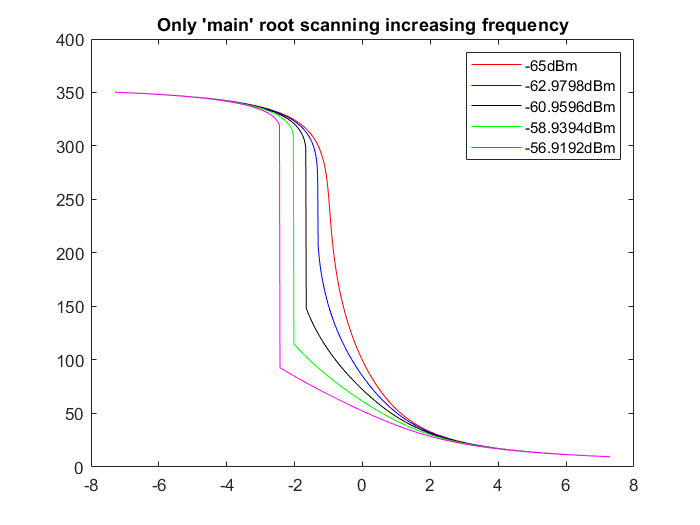

    i = 1;
    j = 1;
    figure
    color_array = ['r', 'b', 'k', 'g', 'm'];
    % i_list = [];
    while i < 100
    %     i_list = [i_list; i];
        main_s11_temp = main_s11(i,:);
        detunings_array_1 = detunings_array(i,:);
        plot(detunings_array, wrapTo360(180/pi*angle(main_s11_temp)), color_array(j))%, 'DisplayName', [num2str(power_input_in_dBm(i) + fridge_attenuation) 'dBm'])
        hold on
        i = i + 20;
        j = j + 1;
    end
    title("Only 'main' root scanning increasing frequency")
    qw = zeros(5,1);
    qw(1) = plot(nan, nan, 'r');hold on
    qw(2) = plot(nan, nan, 'b');
    qw(3) = plot(nan, nan, 'k');
    qw(4) = plot(nan, nan, 'g');
    qw(5) = plot(nan, nan, 'm');
    legend (qw,[num2str(power_input_in_dBm(1) + fridge_attenuation) 'dBm'], [num2str(power_input_in_dBm(21) + fridge_attenuation) 'dBm'], [num2str(power_input_in_dBm(41) + fridge_attenuation) 'dBm'],...
        [num2str(power_input_in_dBm(61) + fridge_attenuation) 'dBm'], [num2str(power_input_in_dBm(81) + fridge_attenuation) 'dBm'])
    hold off

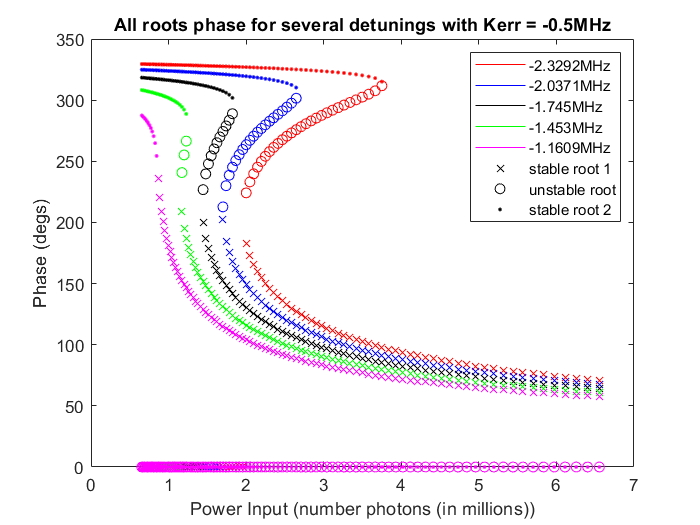

    figure
    color_array = ['r', 'b', 'k', 'g', 'm'];
    i_start = 341;
    i = i_start;
    j = 1;
    while i<i_start + 100
        power_input_array_temp_1 = power_input_array(:,i);
        s11_root_1_temp = s11(:,i,1);
        power_input_array_temp_1 (s11_root_1_temp == 5) = [];
        s11_root_1_temp(s11_root_1_temp == 5) = [];
        
        power_input_array_temp_2 = power_input_array(:,i);
        s11_root_2_temp = s11(:,i,2);
        power_input_array_temp_2 (s11_root_2_temp == 5) = [];
        s11_root_2_temp(s11_root_2_temp == 5) = [];
        
        power_input_array_temp_3 = power_input_array(:,i);
        s11_root_3_temp = s11(:,i,3);
        power_input_array_temp_3 (s11_root_3_temp == 5) = [];
        s11_root_3_temp(s11_root_3_temp == 5) = [];
        
        root_1_color_prop = [color_array(j) 'x'];
        root_2_color_prop = [color_array(j) 'o'];
        root_3_color_prop = [color_array(j) '.'];
        plot(power_input_array_temp_1, wrapTo360(angle(s11_root_1_temp)*180/pi),root_1_color_prop)%,'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + fridge_attenuation) 'dBm, root 1'])
        hold on
        plot(power_input_array_temp_2, wrapTo360(angle(s11_root_2_temp)*180/pi),root_2_color_prop)%,'o')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + fridge_attenuation) 'dBm, root 2'])
        plot(power_input_array_temp_3, wrapTo360(angle(s11_root_3_temp)*180/pi),root_3_color_prop)%,'.')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + fridge_attenuation) 'dBm, root 3'])
        xlabel('Power Input (number photons (in millions))')
        ylabel('Phase (degs)')
        title(['All roots phase for several detunings with Kerr = ' num2str(kerr) 'MHz'])
        i = i + 20;
        j = j + 1;
    end
    i = 341;
    qw = zeros(8,1);
    qw(1) = plot(nan, nan, 'r');hold on
    qw(2) = plot(nan, nan, 'b');
    qw(3) = plot(nan, nan, 'k');
    qw(4) = plot(nan, nan, 'g');
    qw(5) = plot(nan, nan, 'm');
    qw(6) = plot(nan, nan, 'kx');
    qw(7) = plot(nan, nan, 'ko');
    qw(8) = plot(nan, nan, 'k.');
    legend (qw, [num2str(detunings(i)) 'MHz'], [num2str(detunings(i +20)) 'MHz'], [num2str(detunings(i +40) ) 'MHz'],...
        [num2str(detunings(i +60)) 'MHz'], [num2str(detunings(i +80) ) 'MHz'], 'stable root 1', 'unstable root', 'stable root 2')
    hold off

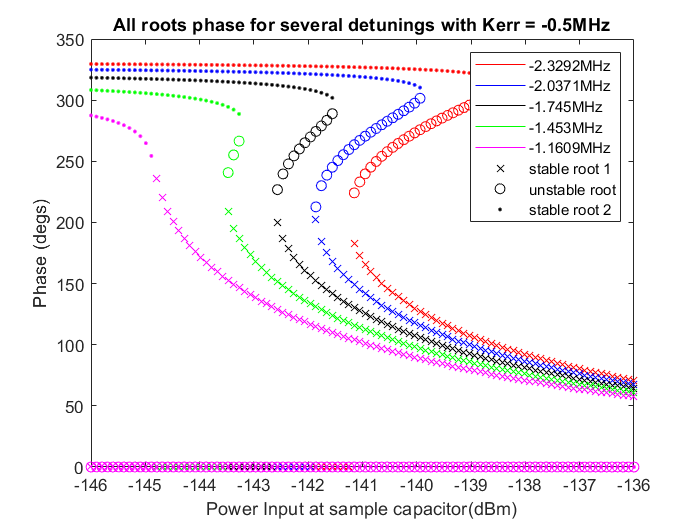

    figure
    color_array = ['r', 'b', 'k', 'g', 'm'];
    i_start = 341;
    i = i_start;
    j = 1;
    while i<i_start + 100
        power_input_array_temp_1 = power_input_array(:,i);
        s11_root_1_temp = s11(:,i,1);
        power_input_array_temp_1 (s11_root_1_temp == 5) = [];
        s11_root_1_temp(s11_root_1_temp == 5) = [];
        
        power_input_array_temp_2 = power_input_array(:,i);
        s11_root_2_temp = s11(:,i,2);
        power_input_array_temp_2 (s11_root_2_temp == 5) = [];
        s11_root_2_temp(s11_root_2_temp == 5) = [];
        
        power_input_array_temp_3 = power_input_array(:,i);
        s11_root_3_temp = s11(:,i,3);
        power_input_array_temp_3 (s11_root_3_temp == 5) = [];
        s11_root_3_temp(s11_root_3_temp == 5) = [];
        
        root_1_color_prop = [color_array(j) 'x'];
        root_2_color_prop = [color_array(j) 'o'];
        root_3_color_prop = [color_array(j) '.'];
        plot(10*log10(power_input_array_temp_1*h*omega_0*1e6/1e-3), wrapTo360(angle(s11_root_1_temp)*180/pi),root_1_color_prop)%,'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + fridge_attenuation) 'dBm, root 1'])
        hold on
        plot(10*log10(power_input_array_temp_2*h*omega_0*1e6/1e-3), wrapTo360(angle(s11_root_2_temp)*180/pi),root_2_color_prop)%,'o')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + fridge_attenuation) 'dBm, root 2'])
        plot(10*log10(power_input_array_temp_3*h*omega_0*1e6/1e-3), wrapTo360(angle(s11_root_3_temp)*180/pi),root_3_color_prop)%,'.')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + fridge_attenuation) 'dBm, root 3'])
        xlabel('Power Input at sample capacitor(dBm)')
        ylabel('Phase (degs)')
        title(['All roots phase for several detunings with Kerr = ' num2str(kerr) 'MHz'])
        i = i + 20;
        j = j + 1;
    end
    i = 341;
    qw = zeros(8,1);
    qw(1) = plot(nan, nan, 'r');hold on
    qw(2) = plot(nan, nan, 'b');
    qw(3) = plot(nan, nan, 'k');
    qw(4) = plot(nan, nan, 'g');
    qw(5) = plot(nan, nan, 'm');
    qw(6) = plot(nan, nan, 'kx');
    qw(7) = plot(nan, nan, 'ko');
    qw(8) = plot(nan, nan, 'k.');
    legend (qw, [num2str(detunings(i)) 'MHz'], [num2str(detunings(i +20)) 'MHz'], [num2str(detunings(i +40) ) 'MHz'],...
        [num2str(detunings(i +60)) 'MHz'], [num2str(detunings(i +80) ) 'MHz'], 'stable root 1', 'unstable root', 'stable root 2')
    hold off

end    

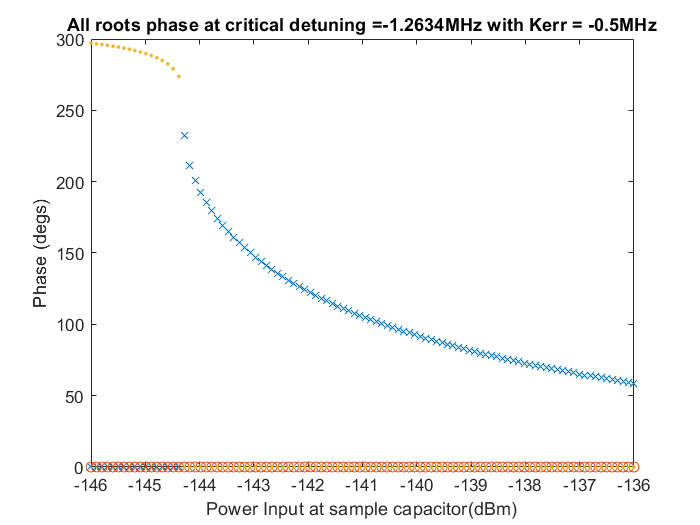

    figure
    power_input_array_temp_1 = power_input_in_numbers;
    s11_critical_detuning_root_1_temp = s11_critical_detuning(:,1);
    power_input_array_temp_1 (s11_critical_detuning_root_1_temp == 5) = [];
    s11_critical_detuning_root_1_temp(s11_critical_detuning_root_1_temp == 5) = [];
    
    power_input_array_temp_2 = power_input_in_numbers;
    s11_critical_detuning_root_2_temp = s11_critical_detuning(:,2);
    power_input_array_temp_2 (s11_critical_detuning_root_2_temp == 5) = [];
    s11_critical_detuning_root_2_temp(s11_critical_detuning_root_2_temp == 5) = [];
    
    power_input_array_temp_3 = power_input_in_numbers;
    s11_critical_detuning_root_3_temp = s11_critical_detuning(:,3);
    power_input_array_temp_3 (s11_critical_detuning_root_3_temp == 5) = [];
    s11_critical_detuning_root_3_temp(s11_critical_detuning_root_3_temp == 5) = [];
    
    plot(10*log10(power_input_array_temp_1*h*omega_0*1e6/1e-3), wrapTo360(angle(s11_critical_detuning_root_1_temp)*180/pi),'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + fridge_attenuation) 'dBm, root 1'])
    hold on
    plot(10*log10(power_input_array_temp_2*h*omega_0*1e6/1e-3), wrapTo360(angle(s11_critical_detuning_root_2_temp)*180/pi),'o')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + fridge_attenuation) 'dBm, root 2'])
    plot(10*log10(power_input_array_temp_3*h*omega_0*1e6/1e-3), wrapTo360(angle(s11_critical_detuning_root_3_temp)*180/pi),'.')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + fridge_attenuation) 'dBm, root 3'])
    xlabel('Power Input at sample capacitor(dBm)')
    ylabel('Phase (degs)')
    title(['All roots phase at critical detuning =' num2str(critical_detuning) 'MHz with Kerr = ' num2str(kerr) 'MHz'])
    hold off

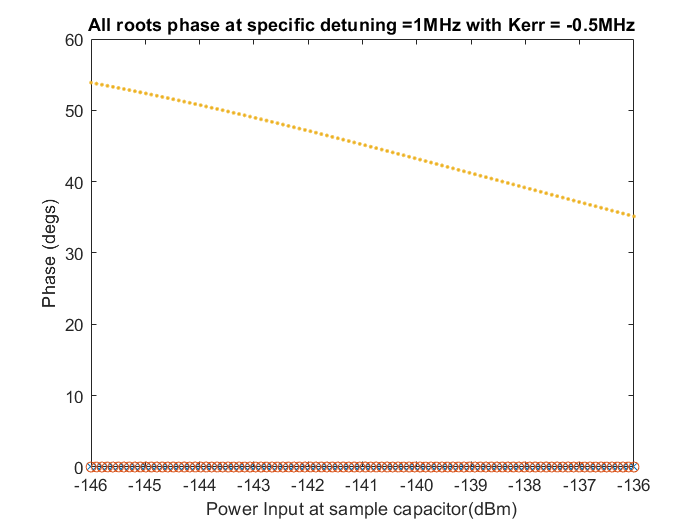

figure
power_input_array_temp_1 = power_input_in_numbers;
s11_critical_detuning_root_1_temp = s11_specific_detuning(:,1);
power_input_array_temp_1 (s11_critical_detuning_root_1_temp == 5) = [];
s11_critical_detuning_root_1_temp(s11_critical_detuning_root_1_temp == 5) = [];

power_input_array_temp_2 = power_input_in_numbers;
s11_critical_detuning_root_2_temp = s11_specific_detuning(:,2);
power_input_array_temp_2 (s11_critical_detuning_root_2_temp == 5) = [];
s11_critical_detuning_root_2_temp(s11_critical_detuning_root_2_temp == 5) = [];

power_input_array_temp_3 = power_input_in_numbers;
s11_critical_detuning_root_3_temp = s11_specific_detuning(:,3);
power_input_array_temp_3 (s11_critical_detuning_root_3_temp == 5) = [];
s11_critical_detuning_root_3_temp(s11_critical_detuning_root_3_temp == 5) = [];

plot(10*log10(power_input_array_temp_1*h*omega_0*1e6/1e-3), wrapTo360(angle(s11_critical_detuning_root_1_temp)*180/pi),'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + fridge_attenuation) 'dBm, root 1'])
hold on
plot(10*log10(power_input_array_temp_2*h*omega_0*1e6/1e-3), wrapTo360(angle(s11_critical_detuning_root_2_temp)*180/pi),'o')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + fridge_attenuation) 'dBm, root 2'])
plot(10*log10(power_input_array_temp_3*h*omega_0*1e6/1e-3), wrapTo360(angle(s11_critical_detuning_root_3_temp)*180/pi),'.')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) + fridge_attenuation) 'dBm, root 3'])
xlabel('Power Input at sample capacitor(dBm)')
ylabel('Phase (degs)')
title(['All roots phase at specific detuning =' num2str(specific_detuning) 'MHz with Kerr = ' num2str(kerr) 'MHz'])
hold off

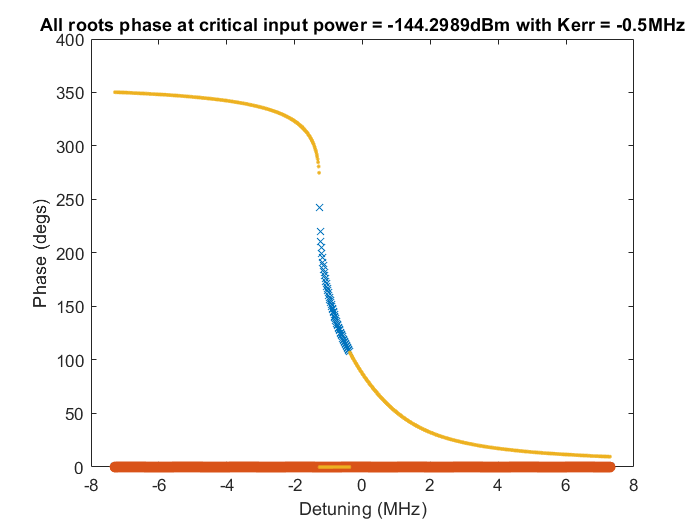

figure
detunings_array_1 = detunings;
s11_root_1_temp = s11_critical_power(:,1);
detunings_array_1 (s11_root_1_temp == 5) = [];
s11_root_1_temp(s11_root_1_temp == 5) = [];

detunings_array_2 = detunings;
s11_root_2_temp = s11_critical_power(:,2);
detunings_array_2 (s11_root_2_temp == 5) = [];
s11_root_2_temp(s11_root_2_temp == 5) = [];

detunings_array_3 = detunings;
s11_root_3_temp = s11_critical_power(:,3);
detunings_array_3 (s11_root_3_temp == 5) = [];
s11_root_3_temp(s11_root_3_temp == 5) = [];

plot(detunings_array_1, wrapTo360(angle(s11_root_1_temp)*180/pi),'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) +  fridge_attenuation) 'dBm, root 1'])
hold on
plot(detunings_array_2, wrapTo360(angle(s11_root_2_temp)*180/pi),'o')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) +  fridge_attenuation) 'dBm, root 2'])
plot(detunings_array_3, wrapTo360(angle(s11_root_3_temp)*180/pi),'.')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) +  fridge_attenuation) 'dBm, root 3'])
xlabel('Detuning (MHz)')
ylabel('Phase (degs)')
title(['All roots phase at critical input power = ' num2str(power_critical_in_dBm) 'dBm with Kerr = ' num2str(kerr) 'MHz'])

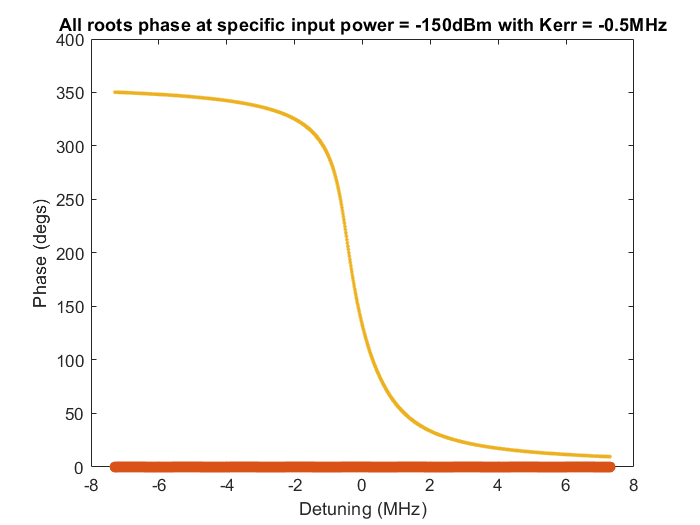

figure
detunings_array_1 = detunings;
s11_root_1_temp = s11_specific_power(:,1);
detunings_array_1 (s11_root_1_temp == 5) = [];
s11_root_1_temp(s11_root_1_temp == 5) = [];

detunings_array_2 = detunings;
s11_root_2_temp = s11_specific_power(:,2);
detunings_array_2 (s11_root_2_temp == 5) = [];
s11_root_2_temp(s11_root_2_temp == 5) = [];

detunings_array_3 = detunings;
s11_root_3_temp = s11_specific_power(:,3);
detunings_array_3 (s11_root_3_temp == 5) = [];
s11_root_3_temp(s11_root_3_temp == 5) = [];

plot(detunings_array_1, wrapTo360(angle(s11_root_1_temp)*180/pi),'x')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) +  fridge_attenuation) 'dBm, root 1'])
hold on
plot(detunings_array_2, wrapTo360(angle(s11_root_2_temp)*180/pi),'o')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) +  fridge_attenuation) 'dBm, root 2'])
plot(detunings_array_3, wrapTo360(angle(s11_root_3_temp)*180/pi),'.')%,'DisplayName',['input power ' num2str(power_input_in_dBm(i) +  fridge_attenuation) 'dBm, root 3'])
xlabel('Detuning (MHz)')
ylabel('Phase (degs)')
title(['All roots phase at specific input power = ' num2str(power_specific_in_dBm) 'dBm with Kerr = ' num2str(kerr) 'MHz'])